% test_solveInitStrain

bridge_clone = bridge_state.clone();
% 输出BaseModel
outputBaseModel(bridge_clone)
% 在MATLAB中恢复为CableSystem
resumeCableSystem(bridge_clone)
% 主缆找形、根据最优设计竖向力Pz_final计算主缆线形和内力、吊索内力
Pz_final = bridge_clone.Result_Iteration.Iter_Pz(bridge_clone.Iter_Optimization);
Y_0 = bridge_clone.solveCableShape(Pz_final);

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    1.693341e+03    0.000e+00    4.333e+02
    1      12    7.475480e+01    0.000e+00    1.070e+02    8.235e+00
    2      18    1.477198e+01    0.000e+00    1.712e+01    4.336e+00
    3      24    1.095465e+01    0.000e+00    7.550e+00    4.353e+00
    4      31    3.548950e+00    0.000e+00    1.119e+01    2.558e+00
    5      37    1.752412e+00    0.000e+00    4.160e+00    2.066e+00
    6      43    1.552397e+00    0.000e+00    5.868e+00    1.635e+00
    7      49    1.407845e-01    0.000e+00    2.177e+00    9.255e-01
    8      55    4.876924e-02    0.000e+00    4.246e-01    4.024e-01

fmincon 已停止，因为目标函数值 4.876924e-02 小于
options.ObjectiveLimit = 5.000000e-02，
且相对最大约束违反值 0.000000e+00 小于 options.Con

ans = 包含以下字段的 struct :
                   X: [0 10 20 30 40 50 60 70 80 90 100 110 120 130 140 150 160 170 180 190 200 210 220 230 240]
                   Y: [-1 -2.3063 -3.6126 -4.9189 -6.2252 -7.0485 -7.8718 -8.6951 -9.5184 -9.8514 -10.1845 -10.5175 -10.8506 -10.5210 -10.1915 -9.8619 -9.5323 -8.6991 -7.8659 -7.0327 -6.1995 -4.8996 -3.5997 -2.2999 -1]
                   Z: [101.8000 86.3394 71.7455 57.9846 45.0253 36.5021 28.5998 21.3004 14.5871 11.4468 8.8054 6.6567 4.9958 6.6567 8.8053 11.4467 14.5869 21.3002 28.5997 36.5020 45.0253 57.9846 71.7455 86.3395 101.8000]
              Strain: [1.4765e-04 1.4189e-04 1.3646e-04 1.3135e-04 1.0530e-04 1.0215e-04 9.9242e-05 9.6558e-05 8.3872e-05 8.2765e-05 8.1847e-05 8.1118e-05 8.1117e-05 8.1846e-05 8.2764e-05 8.3871e-05 9.6564e-05 9.9248e-05 1.0216e-04 1.0531e-04 … ]
    UnstressedLength: [18.4568 17.7375 17.0589 16.4194 13.1645 12.7714 12.4075 12.0722 10.4868 10.3484 10.2337 10.1426 10.1425 10.2336 10.3483 10.4867 12.0729 12.4083 12.7722 13

resumeSymmetrical called!


data_container = DataContainer();
data_container.Data.Y_0 = Y_0;
% 最优设计竖向力Pz_final计算斜拉索内力
X_Pz = bridge_clone.XCoordOfPz;
for i=1:length(bridge_clone.ReplacedStayedCable)
    stayed_cable = bridge_clone.ReplacedStayedCable(i);
    Point_Bottom = stayed_cable.findGirderPoint();
    X_Bottom = [Point_Bottom.X];
    P_girder_z = zeros(1,length(X_Bottom));
    for j=1:length(X_Pz)
        index = abs(X_Pz(j)-X_Bottom) < 1e-5;
        P_girder_z(index) = Pz_final(j);
    end
    stayed_cable.getP(P_girder_z);
end
% 输出CableSystem
Maps_Base = {bridge_clone.Params.Map_OutputedPoint,...
             bridge_clone.Params.Map_MatlabLine2AnsysLine,bridge_clone.Params.Map_AnsysLine2MatlabLine,...
             bridge_clone.Params.Map_MatlabLine2AnsysElem,bridge_clone.Params.Map_AnsysElem2MatlabLine};
bridge_clone.Params.Map_OutputedPoint = cloneMap(Maps_Base{1});
bridge_clone.Params.Map_MatlabLine2AnsysLine = cloneMap(Maps_Base{2});
bridge_clone.Params.Map_AnsysLine2MatlabLine = cloneMap(Maps_Base{3});
bridge_clone.Params.Map_MatlabLine2AnsysElem = cloneMap(Maps_Base{4});
bridge_clone.Params.Map_AnsysElem2MatlabLine = cloneMap(Maps_Base{5});
outputCableSystem(bridge_clone);
% 根据设计竖向力的顺序，排列与之相关的
Map_elem = bridge_clone.Params.Map_MatlabLine2AnsysElem;
points = [];
lines = [];
qs = [];
Areas = [];
StrucutreList = bridge_clone.StructureList;
for i=1:length(StrucutreList)
    structure = StrucutreList{i};
    if strcmp(class(structure),'StayedCable') || strcmp(class(structure),'Hanger')
        points = [points,structure.findGirderPoint];
        lines = [lines,structure.Line];
        qs = [qs,structure.Material.MaterialData.gamma*ones(size(structure.Line))];
        Areas = [Areas,structure.Section.Area];
    else
        continue
    end
end
[sorted_points,index] = points.sort('X');
X_sorted_points = [sorted_points.X];
sorted_lines = lines(index);
num_elem = cell2mat(values(Map_elem,num2cell([sorted_lines.Num])));
bridge_clone.outputAnsysIPC(num_elem);

sorted_qs = qs(index);
sorted_Areas = Areas(index);
W = sorted_Areas.*sorted_qs;
workspace = bridge_clone.OutputMethod.WorkPath;

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    4.873599e-02    0.000e+00    4.148e-01

fmincon 已停止，因为目标函数值 4.873599e-02 小于
options.ObjectiveLimit = 5.000000e-02，
且相对最大约束违反值 0.000000e+00 小于 options.ConstraintTolerance = 1.000000e-06。



ans = 包含以下字段的 struct :
                   X: [0 10 20 30 40 50 60 70 80 90 100 110 120 130 140 150 160 170 180 190 200 210 220 230 240]
                   Y: [-1 -2.3063 -3.6125 -4.9188 -6.2250 -7.0484 -7.8717 -8.6951 -9.5184 -9.8516 -10.1848 -10.5180 -10.8512 -10.5215 -10.1918 -9.8621 -9.5323 -8.6991 -7.8658 -7.0325 -6.1993 -4.8994 -3.5996 -2.2998 -1]
                   Z: [101.8000 86.3400 71.7465 57.9861 45.0271 36.5042 28.6023 21.3031 14.5899 11.4498 8.8084 6.6598 4.9990 6.6598 8.8084 11.4497 14.5898 21.3029 28.6022 36.5042 45.0272 57.9862 71.7466 86.3400 101.8000]
              Strain: [1.4765e-04 1.4190e-04 1.3647e-04 1.3135e-04 1.0530e-04 1.0216e-04 9.9244e-05 9.6561e-05 8.3875e-05 8.2767e-05 8.1850e-05 8.1120e-05 8.1119e-05 8.1849e-05 8.2766e-05 8.3874e-05 9.6566e-05 9.9250e-05 1.0216e-04 1.0531e-04 … ]
    UnstressedLength: [18.4564 17.7371 17.0586 16.4191 13.1644 12.7713 12.4074 12.0721 10.4868 10.3484 10.2337 10.1426 10.1425 10.2336 10.3483 10.4866 12.0728 12.4081 12.7720 13

resumeSymmetrical called!
正在等待ANSYS_Call_MATLAB_ObjFunc.txt...
等到了ANSYS_Call_MATLAB_ObjFunc.txt！
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    4.878979e-02    0.000e+00    4.077e-01

fmincon 已停止，因为目标函数值 4.878979e-02 小于
options.ObjectiveLimit = 5.000000e-02，
且相对最大约束违反值 0.000000e+00 小于 options.ConstraintTolerance = 1.000000e-06。



ans = 包含以下字段的 struct :
                   X: [0 10 20 30 40 50 60 70 80 90 100 110 120 130 140 150 160 170 180 190 200 210 220 230 240]
                   Y: [-1 -2.3059 -3.6118 -4.9177 -6.2237 -7.0467 -7.8697 -8.6928 -9.5158 -9.8488 -10.1818 -10.5148 -10.8478 -10.5183 -10.1888 -9.8592 -9.5297 -8.6968 -7.8638 -7.0309 -6.1979 -4.8984 -3.5990 -2.2995 -1]
                   Z: [101.8000 86.3400 71.7466 57.9862 45.0273 36.5045 28.6025 21.3033 14.5902 11.4501 8.8087 6.6601 4.9993 6.6601 8.8087 11.4500 14.5901 21.3032 28.6024 36.5044 45.0274 57.9863 71.7467 86.3401 101.8000]
              Strain: [1.4765e-04 1.4190e-04 1.3647e-04 1.3135e-04 1.0530e-04 1.0216e-04 9.9245e-05 9.6561e-05 8.3875e-05 8.2768e-05 8.1850e-05 8.1120e-05 8.1119e-05 8.1849e-05 8.2766e-05 8.3874e-05 9.6566e-05 9.9250e-05 1.0216e-04 1.0531e-04 … ]
    UnstressedLength: [18.4563 17.7371 17.0585 16.4191 13.1643 12.7712 12.4074 12.0721 10.4868 10.3484 10.2337 10.1426 10.1424 10.2336 10.3483 10.4866 12.0727 12.4081 12.7719 13

resumeSymmetrical called!
正在等待ANSYS_Call_MATLAB_ObjFunc.txt...
等到了ANSYS_Call_MATLAB_ObjFunc.txt！
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    4.879819e-02    0.000e+00    4.071e-01

fmincon 已停止，因为目标函数值 4.879819e-02 小于
options.ObjectiveLimit = 5.000000e-02，
且相对最大约束违反值 0.000000e+00 小于 options.ConstraintTolerance = 1.000000e-06。



ans = 包含以下字段的 struct :
                   X: [0 10 20 30 40 50 60 70 80 90 100 110 120 130 140 150 160 170 180 190 200 210 220 230 240]
                   Y: [-1 -2.3059 -3.6118 -4.9176 -6.2235 -7.0465 -7.8695 -8.6926 -9.5156 -9.8485 -10.1815 -10.5145 -10.8475 -10.5180 -10.1885 -9.8590 -9.5295 -8.6966 -7.8636 -7.0307 -6.1978 -4.8983 -3.5989 -2.2994 -1]
                   Z: [101.8000 86.3400 71.7466 57.9862 45.0273 36.5045 28.6025 21.3033 14.5902 11.4501 8.8088 6.6602 4.9994 6.6601 8.8087 11.4500 14.5901 21.3032 28.6024 36.5045 45.0274 57.9863 71.7467 86.3401 101.8000]
              Strain: [1.4765e-04 1.4190e-04 1.3647e-04 1.3135e-04 1.0530e-04 1.0216e-04 9.9245e-05 9.6561e-05 8.3875e-05 8.2768e-05 8.1850e-05 8.1121e-05 8.1120e-05 8.1849e-05 8.2767e-05 8.3874e-05 9.6566e-05 9.9250e-05 1.0216e-04 1.0531e-04 … ]
    UnstressedLength: [18.4563 17.7371 17.0585 16.4191 13.1643 12.7712 12.4074 12.0721 10.4868 10.3484 10.2337 10.1426 10.1424 10.2336 10.3483 10.4866 12.0727 12.4081 12.7719 13

resumeSymmetrical called!
正在等待ANSYS_Call_MATLAB_ObjFunc.txt...
等到了ANSYS_Call_MATLAB_ObjFunc.txt！
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    4.879903e-02    0.000e+00    4.071e-01

fmincon 已停止，因为目标函数值 4.879903e-02 小于
options.ObjectiveLimit = 5.000000e-02，
且相对最大约束违反值 0.000000e+00 小于 options.ConstraintTolerance = 1.000000e-06。



ans = 包含以下字段的 struct :
                   X: [0 10 20 30 40 50 60 70 80 90 100 110 120 130 140 150 160 170 180 190 200 210 220 230 240]
                   Y: [-1 -2.3059 -3.6118 -4.9176 -6.2235 -7.0465 -7.8695 -8.6925 -9.5155 -9.8485 -10.1815 -10.5144 -10.8474 -10.5179 -10.1884 -9.8590 -9.5295 -8.6965 -7.8636 -7.0307 -6.1978 -4.8983 -3.5989 -2.2994 -1]
                   Z: [101.8000 86.3400 71.7466 57.9862 45.0274 36.5045 28.6025 21.3034 14.5902 11.4501 8.8088 6.6602 4.9994 6.6601 8.8087 11.4500 14.5901 21.3032 28.6024 36.5045 45.0275 57.9863 71.7467 86.3401 101.8000]
              Strain: [1.4765e-04 1.4190e-04 1.3647e-04 1.3135e-04 1.0530e-04 1.0216e-04 9.9245e-05 9.6561e-05 8.3875e-05 8.2768e-05 8.1850e-05 8.1121e-05 8.1120e-05 8.1849e-05 8.2767e-05 8.3874e-05 9.6566e-05 9.9250e-05 1.0216e-04 1.0531e-04 … ]
    UnstressedLength: [18.4563 17.7371 17.0585 16.4191 13.1643 12.7712 12.4074 12.0721 10.4868 10.3484 10.2337 10.1426 10.1424 10.2336 10.3483 10.4866 12.0727 12.4081 12.7719 13

resumeSymmetrical called!
正在等待ANSYS_Call_MATLAB_ObjFunc.txt...
等到了ANSYS_Call_MATLAB_ObjFunc.txt！
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    4.905903e-02    0.000e+00    4.094e-01

fmincon 已停止，因为目标函数值 4.905903e-02 小于
options.ObjectiveLimit = 5.000000e-02，
且相对最大约束违反值 0.000000e+00 小于 options.ConstraintTolerance = 1.000000e-06。



ans = 包含以下字段的 struct :
                   X: [0 10 20 30 40 50 60 70 80 90 100 110 120 130 140 150 160 170 180 190 200 210 220 230 240]
                   Y: [-1 -2.3061 -3.6122 -4.9183 -6.2245 -7.0474 -7.8702 -8.6931 -9.5160 -9.8489 -10.1818 -10.5147 -10.8476 -10.5181 -10.1885 -9.8590 -9.5295 -8.6965 -7.8636 -7.0307 -6.1977 -4.8983 -3.5989 -2.2994 -1]
                   Z: [101.8000 86.3385 71.7435 57.9817 45.0213 36.4995 28.5985 21.3003 14.5881 11.4486 8.8079 6.6598 4.9996 6.6607 8.8096 11.4512 14.5916 21.3048 28.6040 36.5061 45.0290 57.9876 71.7476 86.3406 101.8000]
              Strain: [1.4767e-04 1.4192e-04 1.3648e-04 1.3137e-04 1.0530e-04 1.0216e-04 9.9246e-05 9.6563e-05 8.3878e-05 8.2771e-05 8.1854e-05 8.1125e-05 8.1125e-05 8.1854e-05 8.2772e-05 8.3879e-05 9.6572e-05 9.9256e-05 1.0217e-04 1.0531e-04 … ]
    UnstressedLength: [18.4576 17.7384 17.0598 16.4203 13.1636 12.7706 12.4069 12.0716 10.4866 10.3482 10.2336 10.1425 10.1425 10.2337 10.3483 10.4867 12.0728 12.4081 12.7719 13

resumeSymmetrical called!
正在等待ANSYS_Call_MATLAB_ObjFunc.txt...
等到了ANSYS_Call_MATLAB_ObjFunc.txt！
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    4.885605e-02    0.000e+00    4.077e-01

fmincon 已停止，因为目标函数值 4.885605e-02 小于
options.ObjectiveLimit = 5.000000e-02，
且相对最大约束违反值 0.000000e+00 小于 options.ConstraintTolerance = 1.000000e-06。



ans = 包含以下字段的 struct :
                   X: [0 10 20 30 40 50 60 70 80 90 100 110 120 130 140 150 160 170 180 190 200 210 220 230 240]
                   Y: [-1 -2.3060 -3.6120 -4.9180 -6.2240 -7.0470 -7.8700 -8.6931 -9.5161 -9.8490 -10.1820 -10.5149 -10.8478 -10.5182 -10.1887 -9.8592 -9.5296 -8.6967 -7.8637 -7.0308 -6.1978 -4.8984 -3.5989 -2.2995 -1]
                   Z: [101.8000 86.3394 71.7454 57.9845 45.0252 36.5019 28.5997 21.3002 14.5869 11.4466 8.8052 6.6565 4.9956 6.6564 8.8050 11.4464 14.5866 21.3000 28.5994 36.5018 45.0251 57.9845 71.7454 86.3394 101.8000]
              Strain: [1.4765e-04 1.4189e-04 1.3646e-04 1.3135e-04 1.0530e-04 1.0215e-04 9.9242e-05 9.6558e-05 8.3872e-05 8.2765e-05 8.1847e-05 8.1118e-05 8.1117e-05 8.1846e-05 8.2764e-05 8.3871e-05 9.6564e-05 9.9248e-05 1.0216e-04 1.0531e-04 … ]
    UnstressedLength: [18.4568 17.7375 17.0589 16.4194 13.1645 12.7714 12.4075 12.0721 10.4868 10.3484 10.2337 10.1426 10.1425 10.2336 10.3483 10.4867 12.0729 12.4083 12.7721 13

resumeSymmetrical called!
正在等待ANSYS_Call_MATLAB_ObjFunc.txt...
等到了ANSYS_Call_MATLAB_ObjFunc.txt！
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    4.869135e-02    0.000e+00    4.165e-01

fmincon 已停止，因为目标函数值 4.869135e-02 小于
options.ObjectiveLimit = 5.000000e-02，
且相对最大约束违反值 0.000000e+00 小于 options.ConstraintTolerance = 1.000000e-06。



ans = 包含以下字段的 struct :
                   X: [0 10 20 30 40 50 60 70 80 90 100 110 120 130 140 150 160 170 180 190 200 210 220 230 240]
                   Y: [-1 -2.3064 -3.6129 -4.9193 -6.2258 -7.0493 -7.8729 -8.6965 -9.5201 -9.8532 -10.1862 -10.5192 -10.8523 -10.5224 -10.1926 -9.8627 -9.5328 -8.6995 -7.8661 -7.0328 -6.1994 -4.8996 -3.5997 -2.2999 -1]
                   Z: [101.8000 86.3397 71.7458 57.9849 45.0255 36.5016 28.5986 21.2984 14.5842 11.4453 8.8052 6.6578 4.9982 6.6597 8.8090 11.4510 14.5917 21.3050 28.6044 36.5066 45.0297 57.9882 71.7480 86.3408 101.8000]
              Strain: [1.4767e-04 1.4191e-04 1.3648e-04 1.3137e-04 1.0532e-04 1.0217e-04 9.9260e-05 9.6576e-05 8.3880e-05 8.2774e-05 8.1857e-05 8.1128e-05 8.1129e-05 8.1859e-05 8.2777e-05 8.3884e-05 9.6578e-05 9.9262e-05 1.0217e-04 1.0532e-04 … ]
    UnstressedLength: [18.4566 17.7374 17.0589 16.4195 13.1650 12.7719 12.4081 12.0727 10.4864 10.3481 10.2335 10.1424 10.1426 10.2338 10.3484 10.4868 12.0729 12.4083 12.7720 13

resumeSymmetrical called!
正在等待ANSYS_Call_MATLAB_ObjFunc.txt...
等到了ANSYS_Call_MATLAB_ObjFunc.txt！
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    4.875657e-02    0.000e+00    4.104e-01

fmincon 已停止，因为目标函数值 4.875657e-02 小于
options.ObjectiveLimit = 5.000000e-02，
且相对最大约束违反值 0.000000e+00 小于 options.ConstraintTolerance = 1.000000e-06。



ans = 包含以下字段的 struct :
                   X: [0 10 20 30 40 50 60 70 80 90 100 110 120 130 140 150 160 170 180 190 200 210 220 230 240]
                   Y: [-1 -2.3061 -3.6122 -4.9183 -6.2244 -7.0477 -7.8710 -8.6942 -9.5175 -9.8507 -10.1838 -10.5170 -10.8501 -10.5203 -10.1904 -9.8606 -9.5307 -8.6976 -7.8644 -7.0313 -6.1982 -4.8986 -3.5991 -2.2995 -1]
                   Z: [101.8000 86.3408 71.7481 57.9882 45.0297 36.5065 28.6042 21.3046 14.5910 11.4499 8.8074 6.6577 4.9957 6.6576 8.8073 11.4496 14.5907 21.3043 28.6040 36.5064 45.0296 57.9882 71.7481 86.3408 101.8000]
              Strain: [1.4767e-04 1.4191e-04 1.3648e-04 1.3136e-04 1.0532e-04 1.0217e-04 9.9261e-05 9.6577e-05 8.3889e-05 8.2781e-05 8.1864e-05 8.1134e-05 8.1133e-05 8.1863e-05 8.2781e-05 8.3888e-05 9.6583e-05 9.9267e-05 1.0218e-04 1.0532e-04 … ]
    UnstressedLength: [18.4556 17.7365 17.0581 16.4187 13.1645 12.7714 12.4076 12.0723 10.4870 10.3486 10.2340 10.1427 10.1427 10.2339 10.3486 10.4870 12.0731 12.4084 12.7722 13

resumeSymmetrical called!
正在等待ANSYS_Call_MATLAB_ObjFunc.txt...
等到了ANSYS_Call_MATLAB_ObjFunc.txt！
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    4.863118e-02    0.000e+00    4.116e-01

fmincon 已停止，因为目标函数值 4.863118e-02 小于
options.ObjectiveLimit = 5.000000e-02，
且相对最大约束违反值 0.000000e+00 小于 options.ConstraintTolerance = 1.000000e-06。



ans = 包含以下字段的 struct :
                   X: [0 10 20 30 40 50 60 70 80 90 100 110 120 130 140 150 160 170 180 190 200 210 220 230 240]
                   Y: [-1 -2.3061 -3.6122 -4.9183 -6.2244 -7.0476 -7.8709 -8.6942 -9.5175 -9.8509 -10.1842 -10.5175 -10.8509 -10.5213 -10.1918 -9.8623 -9.5327 -8.6994 -7.8660 -7.0326 -6.1993 -4.8994 -3.5996 -2.2998 -1]
                   Z: [101.8000 86.3408 71.7481 57.9882 45.0298 36.5069 28.6048 21.3055 14.5921 11.4514 8.8094 6.6600 4.9985 6.6581 8.8055 11.4455 14.5843 21.2985 28.5987 36.5018 45.0258 57.9852 71.7460 86.3398 101.8000]
              Strain: [1.4766e-04 1.4191e-04 1.3648e-04 1.3136e-04 1.0531e-04 1.0217e-04 9.9256e-05 9.6573e-05 8.3886e-05 8.2778e-05 8.1860e-05 8.1131e-05 8.1127e-05 8.1856e-05 8.2773e-05 8.3880e-05 9.6582e-05 9.9266e-05 1.0218e-04 1.0532e-04 … ]
    UnstressedLength: [18.4556 17.7365 17.0581 16.4187 13.1644 12.7713 12.4075 12.0722 10.4869 10.3486 10.2339 10.1427 10.1423 10.2334 10.3479 10.4862 12.0734 12.4088 12.7726 13

resumeSymmetrical called!
正在等待ANSYS_Call_MATLAB_ObjFunc.txt...
等到了ANSYS_Call_MATLAB_ObjFunc.txt！
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    4.871611e-02    0.000e+00    4.087e-01

fmincon 已停止，因为目标函数值 4.871611e-02 小于
options.ObjectiveLimit = 5.000000e-02，
且相对最大约束违反值 0.000000e+00 小于 options.ConstraintTolerance = 1.000000e-06。



ans = 包含以下字段的 struct :
                   X: [0 10 20 30 40 50 60 70 80 90 100 110 120 130 140 150 160 170 180 190 200 210 220 230 240]
                   Y: [-1 -2.3060 -3.6120 -4.9180 -6.2240 -7.0471 -7.8702 -8.6933 -9.5165 -9.8496 -10.1827 -10.5159 -10.8490 -10.5196 -10.1901 -9.8606 -9.5312 -8.6980 -7.8649 -7.0318 -6.1987 -4.8990 -3.5993 -2.2997 -1]
                   Z: [101.8000 86.3394 71.7453 57.9844 45.0250 36.5018 28.5996 21.3001 14.5868 11.4465 8.8051 6.6564 4.9956 6.6564 8.8051 11.4465 14.5867 21.3000 28.5995 36.5018 45.0251 57.9845 71.7454 86.3394 101.8000]
              Strain: [1.4765e-04 1.4189e-04 1.3646e-04 1.3135e-04 1.0530e-04 1.0215e-04 9.9242e-05 9.6558e-05 8.3872e-05 8.2765e-05 8.1847e-05 8.1118e-05 8.1117e-05 8.1846e-05 8.2764e-05 8.3871e-05 9.6564e-05 9.9248e-05 1.0216e-04 1.0531e-04 … ]
    UnstressedLength: [18.4568 17.7375 17.0589 16.4194 13.1645 12.7714 12.4075 12.0721 10.4868 10.3484 10.2337 10.1426 10.1425 10.2336 10.3483 10.4867 12.0729 12.4083 12.7722 13

resumeSymmetrical called!
正在等待ANSYS_Call_MATLAB_ObjFunc.txt...
等到了ANSYS_Call_MATLAB_ObjFunc.txt！
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    4.865247e-02    0.000e+00    4.144e-01

fmincon 已停止，因为目标函数值 4.865247e-02 小于
options.ObjectiveLimit = 5.000000e-02，
且相对最大约束违反值 0.000000e+00 小于 options.ConstraintTolerance = 1.000000e-06。



ans = 包含以下字段的 struct :
                   X: [0 10 20 30 40 50 60 70 80 90 100 110 120 130 140 150 160 170 180 190 200 210 220 230 240]
                   Y: [-1 -2.3063 -3.6125 -4.9188 -6.2251 -7.0485 -7.8719 -8.6953 -9.5187 -9.8519 -10.1852 -10.5185 -10.8517 -10.5221 -10.1924 -9.8627 -9.5331 -8.6999 -7.8667 -7.0335 -6.2003 -4.9002 -3.6001 -2.3001 -1]
                   Z: [101.8000 86.3403 71.7471 57.9870 45.0282 36.5053 28.6033 21.3040 14.5907 11.4503 8.8086 6.6597 4.9985 6.6587 8.8067 11.4474 14.5869 21.2992 28.5976 36.4987 45.0207 57.9812 71.7432 86.3384 101.8000]
              Strain: [1.4766e-04 1.4190e-04 1.3647e-04 1.3135e-04 1.0531e-04 1.0216e-04 9.9250e-05 9.6566e-05 8.3879e-05 8.2772e-05 8.1855e-05 8.1125e-05 8.1123e-05 8.1852e-05 8.2769e-05 8.3876e-05 9.6567e-05 9.9251e-05 1.0216e-04 1.0531e-04 … ]
    UnstressedLength: [18.4561 17.7369 17.0584 16.4190 13.1644 12.7713 12.4075 12.0721 10.4869 10.3485 10.2338 10.1426 10.1424 10.2335 10.3481 10.4865 12.0723 12.4076 12.7714 13

resumeSymmetrical called!
正在等待ANSYS_Call_MATLAB_ObjFunc.txt...
等到了ANSYS_Call_MATLAB_ObjFunc.txt！
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    4.873389e-02    0.000e+00    4.089e-01

fmincon 已停止，因为目标函数值 4.873389e-02 小于
options.ObjectiveLimit = 5.000000e-02，
且相对最大约束违反值 0.000000e+00 小于 options.ConstraintTolerance = 1.000000e-06。



ans = 包含以下字段的 struct :
                   X: [0 10 20 30 40 50 60 70 80 90 100 110 120 130 140 150 160 170 180 190 200 210 220 230 240]
                   Y: [-1 -2.3060 -3.6120 -4.9179 -6.2239 -7.0470 -7.8701 -8.6933 -9.5164 -9.8495 -10.1825 -10.5156 -10.8487 -10.5192 -10.1897 -9.8602 -9.5307 -8.6977 -7.8646 -7.0316 -6.1985 -4.8989 -3.5993 -2.2996 -1]
                   Z: [101.8000 86.3399 71.7463 57.9858 45.0268 36.5039 28.6019 21.3027 14.5895 11.4493 8.8080 6.6594 4.9986 6.6593 8.8079 11.4493 14.5894 21.3026 28.6018 36.5039 45.0270 57.9860 71.7464 86.3400 101.8000]
              Strain: [1.4765e-04 1.4190e-04 1.3647e-04 1.3135e-04 1.0530e-04 1.0216e-04 9.9244e-05 9.6560e-05 8.3874e-05 8.2767e-05 8.1849e-05 8.1120e-05 8.1119e-05 8.1849e-05 8.2766e-05 8.3873e-05 9.6566e-05 9.9250e-05 1.0216e-04 1.0531e-04 … ]
    UnstressedLength: [18.4564 17.7372 17.0586 16.4192 13.1644 12.7713 12.4074 12.0721 10.4868 10.3484 10.2337 10.1426 10.1424 10.2336 10.3483 10.4866 12.0728 12.4082 12.7720 13

resumeSymmetrical called!
正在等待ANSYS_Call_MATLAB_ObjFunc.txt...
等到了ANSYS_Call_MATLAB_ObjFunc.txt！
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    4.877739e-02    0.000e+00    4.089e-01

fmincon 已停止，因为目标函数值 4.877739e-02 小于
options.ObjectiveLimit = 5.000000e-02，
且相对最大约束违反值 0.000000e+00 小于 options.ConstraintTolerance = 1.000000e-06。



ans = 包含以下字段的 struct :
                   X: [0 10 20 30 40 50 60 70 80 90 100 110 120 130 140 150 160 170 180 190 200 210 220 230 240]
                   Y: [-1 -2.3060 -3.6120 -4.9179 -6.2239 -7.0470 -7.8701 -8.6932 -9.5163 -9.8493 -10.1823 -10.5154 -10.8484 -10.5188 -10.1893 -9.8597 -9.5302 -8.6972 -7.8642 -7.0312 -6.1982 -4.8986 -3.5991 -2.2995 -1]
                   Z: [101.8000 86.3399 71.7463 57.9858 45.0268 36.5039 28.6019 21.3026 14.5895 11.4493 8.8079 6.6593 4.9985 6.6593 8.8079 11.4492 14.5893 21.3025 28.6017 36.5038 45.0269 57.9859 71.7464 86.3399 101.8000]
              Strain: [1.4765e-04 1.4190e-04 1.3647e-04 1.3135e-04 1.0530e-04 1.0216e-04 9.9244e-05 9.6560e-05 8.3874e-05 8.2767e-05 8.1849e-05 8.1120e-05 8.1119e-05 8.1849e-05 8.2766e-05 8.3873e-05 9.6566e-05 9.9250e-05 1.0216e-04 1.0531e-04 … ]
    UnstressedLength: [18.4564 17.7372 17.0586 16.4192 13.1644 12.7713 12.4074 12.0721 10.4868 10.3484 10.2337 10.1426 10.1424 10.2336 10.3483 10.4866 12.0728 12.4082 12.7720 13

resumeSymmetrical called!
正在等待ANSYS_Call_MATLAB_ObjFunc.txt...
等到了ANSYS_Call_MATLAB_ObjFunc.txt！
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    4.877552e-02    0.000e+00    4.090e-01

fmincon 已停止，因为目标函数值 4.877552e-02 小于
options.ObjectiveLimit = 5.000000e-02，
且相对最大约束违反值 0.000000e+00 小于 options.ConstraintTolerance = 1.000000e-06。



ans = 包含以下字段的 struct :
                   X: [0 10 20 30 40 50 60 70 80 90 100 110 120 130 140 150 160 170 180 190 200 210 220 230 240]
                   Y: [-1 -2.3060 -3.6120 -4.9179 -6.2239 -7.0470 -7.8701 -8.6932 -9.5163 -9.8493 -10.1824 -10.5154 -10.8484 -10.5189 -10.1893 -9.8598 -9.5302 -8.6972 -7.8642 -7.0312 -6.1982 -4.8986 -3.5991 -2.2995 -1]
                   Z: [101.8000 86.3399 71.7463 57.9858 45.0268 36.5039 28.6019 21.3026 14.5895 11.4493 8.8079 6.6593 4.9985 6.6593 8.8079 11.4492 14.5893 21.3025 28.6017 36.5038 45.0269 57.9859 71.7464 86.3399 101.8000]
              Strain: [1.4765e-04 1.4190e-04 1.3647e-04 1.3135e-04 1.0530e-04 1.0216e-04 9.9244e-05 9.6560e-05 8.3874e-05 8.2767e-05 8.1849e-05 8.1120e-05 8.1119e-05 8.1849e-05 8.2766e-05 8.3873e-05 9.6566e-05 9.9250e-05 1.0216e-04 1.0531e-04 … ]
    UnstressedLength: [18.4564 17.7372 17.0586 16.4192 13.1644 12.7713 12.4074 12.0721 10.4868 10.3484 10.2337 10.1426 10.1424 10.2336 10.3483 10.4866 12.0728 12.4082 12.7720 13

resumeSymmetrical called!
正在等待ANSYS_Call_MATLAB_ObjFunc.txt...
等到了ANSYS_Call_MATLAB_ObjFunc.txt！
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    8.634136e-01    0.000e+00    7.820e+00
    1      19    3.763530e-01    0.000e+00    2.964e+00    2.334e-01
    2      26    1.615365e-01    0.000e+00    2.447e+00    2.615e-01
    3      34    1.166432e-01    0.000e+00    1.139e+00    1.706e-01
    4      41    4.107093e-02    0.000e+00    1.507e+00    2.262e-01

fmincon 已停止，因为目标函数值 4.107093e-02 小于
options.ObjectiveLimit = 5.000000e-02，
且相对最大约束违反值 0.000000e+00 小于 options.ConstraintTolerance = 1.000000e-06。



ans = 包含以下字段的 struct :
                   X: [0 10 20 30 40 50 60 70 80 90 100 110 120 130 140 150 160 170 180 190 200 210 220 230 240]
                   Y: [-1 -2.1814 -3.3628 -4.5442 -5.7255 -6.7138 -7.7020 -8.6902 -9.6784 -9.9260 -10.1736 -10.4212 -10.6688 -10.3326 -9.9963 -9.6601 -9.3239 -8.5205 -7.7172 -6.9139 -6.1106 -4.8329 -3.5553 -2.2776 -1]
                   Z: [101.8000 87.0595 73.2053 60.2018 48.0157 38.0575 28.8039 20.2312 12.3173 9.7109 7.6255 6.0556 4.9972 6.6760 8.8715 11.5893 14.8365 21.3427 28.4636 36.2177 44.6247 57.6070 71.4396 86.1580 101.8000]
              Strain: [1.3490e-04 1.2942e-04 1.2428e-04 1.1946e-04 1.0690e-04 1.0322e-04 9.9808e-05 9.6651e-05 7.8105e-05 7.7206e-05 7.6506e-05 7.6003e-05 7.6658e-05 7.7400e-05 7.8341e-05 7.9483e-05 9.0351e-05 9.2961e-05 9.5810e-05 9.8905e-05 … ]
    UnstressedLength: [17.8498 17.1254 16.4450 15.8069 14.1464 13.6597 13.2081 12.7904 10.3373 10.2184 10.1258 10.0592 10.1458 10.2440 10.3684 10.5196 11.9571 12.3023 12.6792 13.0

resumeSymmetrical called!
正在等待ANSYS_Call_MATLAB_ObjFunc.txt...
等到了ANSYS_Call_MATLAB_ObjFunc.txt！
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    8.647540e-01    0.000e+00    7.815e+00
    1      19    4.089840e-01    0.000e+00    5.198e+00    2.451e-01
    2      26    2.638046e-01    0.000e+00    3.130e+00    2.357e-01
    3      32    1.000619e-01    0.000e+00    6.238e-01    1.869e-01
    4      39    5.614835e-02    0.000e+00    5.829e-01    3.715e-01
    5      45    2.507873e-02    0.000e+00    2.704e-01    2.482e-01

fmincon 已停止，因为目标函数值 2.507873e-02 小于
options.ObjectiveLimit = 5.000000e-02，
且相对最大约束违反值 0.000000e+00 小于 options.ConstraintTolerance = 1.000000e-06。



ans = 包含以下字段的 struct :
                   X: [0 10 20 30 40 50 60 70 80 90 100 110 120 130 140 150 160 170 180 190 200 210 220 230 240]
                   Y: [-1 -2.2023 -3.4046 -4.6069 -5.8092 -6.8313 -7.8535 -8.8756 -9.8977 -10.1208 -10.3439 -10.5670 -10.7900 -10.4404 -10.0907 -9.7411 -9.3914 -8.5894 -7.7874 -6.9854 -6.1834 -4.8876 -3.5917 -2.2959 -1]
                   Z: [101.8000 87.0536 73.1940 60.1855 47.9947 38.0436 28.7971 20.2314 12.3246 9.7168 7.6300 6.0588 4.9991 6.6769 8.8714 11.5884 14.8347 21.3413 28.4628 36.2174 44.6251 57.6071 71.4395 86.1578 101.8000]
              Strain: [1.3493e-04 1.2945e-04 1.2431e-04 1.1948e-04 1.0687e-04 1.0319e-04 9.9783e-05 9.6628e-05 7.8095e-05 7.7196e-05 7.6496e-05 7.5992e-05 7.6652e-05 7.7394e-05 7.8334e-05 7.9476e-05 9.0342e-05 9.2953e-05 9.5802e-05 9.8897e-05 … ]
    UnstressedLength: [17.8560 17.1312 16.4505 15.8121 14.1438 13.6574 13.2061 12.7888 10.3371 10.2181 10.1254 10.0588 10.1461 10.2442 10.3686 10.5197 11.9572 12.3025 12.6794 13

resumeSymmetrical called!
正在等待ANSYS_Call_MATLAB_ObjFunc.txt...
等到了ANSYS_Call_MATLAB_ObjFunc.txt！
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    2.464940e-02    0.000e+00    1.965e-01

fmincon 已停止，因为目标函数值 2.464940e-02 小于
options.ObjectiveLimit = 5.000000e-02，
且相对最大约束违反值 0.000000e+00 小于 options.ConstraintTolerance = 1.000000e-06。



ans = 包含以下字段的 struct :
                   X: [0 10 20 30 40 50 60 70 80 90 100 110 120 130 140 150 160 170 180 190 200 210 220 230 240]
                   Y: [-1 -2.2019 -3.4039 -4.6058 -5.8078 -6.8295 -7.8512 -8.8729 -9.8946 -10.1177 -10.3409 -10.5640 -10.7871 -10.4377 -10.0883 -9.7390 -9.3896 -8.5878 -7.7860 -6.9843 -6.1825 -4.8869 -3.5912 -2.2956 -1]
                   Z: [101.8000 87.0538 73.1943 60.1860 47.9953 38.0442 28.7978 20.2321 12.3253 9.7176 7.6308 6.0596 4.9999 6.6777 8.8722 11.5891 14.8355 21.3420 28.4634 36.2180 44.6256 57.6075 71.4398 86.1580 101.8000]
              Strain: [1.3493e-04 1.2945e-04 1.2431e-04 1.1948e-04 1.0687e-04 1.0320e-04 9.9784e-05 9.6629e-05 7.8096e-05 7.7197e-05 7.6496e-05 7.5992e-05 7.6652e-05 7.7394e-05 7.8335e-05 7.9477e-05 9.0342e-05 9.2953e-05 9.5802e-05 9.8897e-05 … ]
    UnstressedLength: [17.8559 17.1311 16.4504 15.8120 14.1438 13.6574 13.2061 12.7888 10.3371 10.2181 10.1254 10.0588 10.1461 10.2442 10.3686 10.5197 11.9572 12.3024 12.6794 13

resumeSymmetrical called!
正在等待ANSYS_Call_MATLAB_ObjFunc.txt...
等到了ANSYS_Call_MATLAB_ObjFunc.txt！
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    2.500379e-02    0.000e+00    2.093e-01

fmincon 已停止，因为目标函数值 2.500379e-02 小于
options.ObjectiveLimit = 5.000000e-02，
且相对最大约束违反值 0.000000e+00 小于 options.ConstraintTolerance = 1.000000e-06。



ans = 包含以下字段的 struct :
                   X: [0 10 20 30 40 50 60 70 80 90 100 110 120 130 140 150 160 170 180 190 200 210 220 230 240]
                   Y: [-1 -2.2023 -3.4045 -4.6068 -5.8090 -6.8310 -7.8530 -8.8750 -9.8970 -10.1202 -10.3435 -10.5668 -10.7900 -10.4404 -10.0909 -9.7413 -9.3918 -8.5897 -7.7877 -6.9857 -6.1836 -4.8877 -3.5918 -2.2959 -1]
                   Z: [101.8000 87.0532 73.1933 60.1845 47.9934 38.0420 28.7952 20.2293 12.3222 9.7144 7.6276 6.0563 4.9966 6.6744 8.8690 11.5860 14.8324 21.3392 28.4608 36.2156 44.6235 57.6058 71.4386 86.1574 101.8000]
              Strain: [1.3493e-04 1.2945e-04 1.2431e-04 1.1948e-04 1.0687e-04 1.0319e-04 9.9782e-05 9.6627e-05 7.8094e-05 7.7194e-05 7.6494e-05 7.5990e-05 7.6650e-05 7.7392e-05 7.8332e-05 7.9475e-05 9.0341e-05 9.2951e-05 9.5800e-05 9.8896e-05 … ]
    UnstressedLength: [17.8563 17.1315 16.4508 15.8123 14.1440 13.6576 13.2063 12.7889 10.3371 10.2181 10.1254 10.0588 10.1461 10.2442 10.3687 10.5198 11.9573 12.3026 12.6796 13

resumeSymmetrical called!
正在等待ANSYS_Call_MATLAB_ObjFunc.txt...
等到了ANSYS_Call_MATLAB_ObjFunc.txt！
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    2.513079e-02    0.000e+00    2.127e-01

fmincon 已停止，因为目标函数值 2.513079e-02 小于
options.ObjectiveLimit = 5.000000e-02，
且相对最大约束违反值 0.000000e+00 小于 options.ConstraintTolerance = 1.000000e-06。



ans = 包含以下字段的 struct :
                   X: [0 10 20 30 40 50 60 70 80 90 100 110 120 130 140 150 160 170 180 190 200 210 220 230 240]
                   Y: [-1 -2.2025 -3.4050 -4.6075 -5.8099 -6.8318 -7.8536 -8.8755 -9.8974 -10.1205 -10.3437 -10.5669 -10.7901 -10.4405 -10.0909 -9.7412 -9.3916 -8.5896 -7.7876 -6.9855 -6.1835 -4.8876 -3.5918 -2.2959 -1]
                   Z: [101.8000 87.0519 73.1906 60.1805 47.9881 38.0381 28.7927 20.2280 12.3221 9.7150 7.6288 6.0581 4.9990 6.6771 8.8720 11.5893 14.8359 21.3426 28.4642 36.2188 44.6265 57.6082 71.4403 86.1583 101.8000]
              Strain: [1.3495e-04 1.2947e-04 1.2433e-04 1.1950e-04 1.0687e-04 1.0319e-04 9.9784e-05 9.6629e-05 7.8099e-05 7.7200e-05 7.6499e-05 7.5996e-05 7.6657e-05 7.7398e-05 7.8339e-05 7.9482e-05 9.0348e-05 9.2958e-05 9.5807e-05 9.8903e-05 … ]
    UnstressedLength: [17.8574 17.1326 16.4519 15.8134 14.1430 13.6567 13.2055 12.7882 10.3369 10.2180 10.1253 10.0587 10.1461 10.2443 10.3687 10.5198 11.9573 12.3026 12.6795 13

resumeSymmetrical called!
正在等待ANSYS_Call_MATLAB_ObjFunc.txt...
等到了ANSYS_Call_MATLAB_ObjFunc.txt！
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    2.475224e-02    0.000e+00    1.966e-01

fmincon 已停止，因为目标函数值 2.475224e-02 小于
options.ObjectiveLimit = 5.000000e-02，
且相对最大约束违反值 0.000000e+00 小于 options.ConstraintTolerance = 1.000000e-06。



ans = 包含以下字段的 struct :
                   X: [0 10 20 30 40 50 60 70 80 90 100 110 120 130 140 150 160 170 180 190 200 210 220 230 240]
                   Y: [-1 -2.2021 -3.4042 -4.6063 -5.8084 -6.8303 -7.8521 -8.8739 -9.8957 -10.1188 -10.3419 -10.5650 -10.7880 -10.4386 -10.0891 -9.7396 -9.3901 -8.5883 -7.7864 -6.9846 -6.1828 -4.8871 -3.5914 -2.2957 -1]
                   Z: [101.8000 87.0533 73.1933 60.1845 47.9935 38.0421 28.7953 20.2293 12.3223 9.7144 7.6276 6.0563 4.9966 6.6744 8.8689 11.5859 14.8324 21.3391 28.4607 36.2155 44.6234 57.6058 71.4386 86.1574 101.8000]
              Strain: [1.3493e-04 1.2945e-04 1.2431e-04 1.1948e-04 1.0687e-04 1.0319e-04 9.9781e-05 9.6627e-05 7.8094e-05 7.7194e-05 7.6494e-05 7.5990e-05 7.6650e-05 7.7392e-05 7.8332e-05 7.9475e-05 9.0341e-05 9.2951e-05 9.5800e-05 9.8896e-05 … ]
    UnstressedLength: [17.8562 17.1315 16.4507 15.8123 14.1440 13.6576 13.2063 12.7889 10.3371 10.2181 10.1254 10.0588 10.1461 10.2442 10.3687 10.5198 11.9573 12.3026 12.6796 13

resumeSymmetrical called!
正在等待ANSYS_Call_MATLAB_ObjFunc.txt...
等到了ANSYS_Call_MATLAB_ObjFunc.txt！
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    2.516157e-02    0.000e+00    2.181e-01

fmincon 已停止，因为目标函数值 2.516157e-02 小于
options.ObjectiveLimit = 5.000000e-02，
且相对最大约束违反值 0.000000e+00 小于 options.ConstraintTolerance = 1.000000e-06。



ans = 包含以下字段的 struct :
                   X: [0 10 20 30 40 50 60 70 80 90 100 110 120 130 140 150 160 170 180 190 200 210 220 230 240]
                   Y: [-1 -2.2024 -3.4048 -4.6073 -5.8097 -6.8319 -7.8541 -8.8762 -9.8984 -10.1215 -10.3446 -10.5676 -10.7907 -10.4410 -10.0913 -9.7416 -9.3919 -8.5898 -7.7878 -6.9857 -6.1836 -4.8877 -3.5918 -2.2959 -1]
                   Z: [101.8000 87.0534 73.1934 60.1845 47.9932 38.0413 28.7939 20.2273 12.3195 9.7131 7.6276 6.0575 4.9990 6.6776 8.8728 11.5905 14.8374 21.3443 28.4659 36.2206 44.6282 57.6097 71.4414 86.1589 101.8000]
              Strain: [1.3495e-04 1.2947e-04 1.2433e-04 1.1950e-04 1.0689e-04 1.0321e-04 9.9800e-05 9.6645e-05 7.8103e-05 7.7204e-05 7.6504e-05 7.6000e-05 7.6662e-05 7.7404e-05 7.8345e-05 7.9488e-05 9.0355e-05 9.2965e-05 9.5814e-05 9.8909e-05 … ]
    UnstressedLength: [17.8562 17.1315 16.4509 15.8125 14.1444 13.6580 13.2067 12.7894 10.3367 10.2178 10.1252 10.0586 10.1462 10.2444 10.3688 10.5199 11.9574 12.3026 12.6795 13

resumeSymmetrical called!
正在等待ANSYS_Call_MATLAB_ObjFunc.txt...
等到了ANSYS_Call_MATLAB_ObjFunc.txt！
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    2.530118e-02    0.000e+00    2.237e-01

fmincon 已停止，因为目标函数值 2.530118e-02 小于
options.ObjectiveLimit = 5.000000e-02，
且相对最大约束违反值 0.000000e+00 小于 options.ConstraintTolerance = 1.000000e-06。



ans = 包含以下字段的 struct :
                   X: [0 10 20 30 40 50 60 70 80 90 100 110 120 130 140 150 160 170 180 190 200 210 220 230 240]
                   Y: [-1 -2.2023 -3.4046 -4.6069 -5.8092 -6.8313 -7.8534 -8.8755 -9.8976 -10.1209 -10.3442 -10.5676 -10.7909 -10.4411 -10.0912 -9.7414 -9.3915 -8.5894 -7.7873 -6.9853 -6.1832 -4.8874 -3.5916 -2.2958 -1]
                   Z: [101.8000 87.0551 73.1968 60.1894 47.9995 38.0487 28.8024 20.2368 12.3299 9.7211 7.6332 6.0607 4.9997 6.6786 8.8742 11.5922 14.8394 21.3463 28.4679 36.2226 44.6302 57.6112 71.4425 86.1595 101.8000]
              Strain: [1.3495e-04 1.2947e-04 1.2433e-04 1.1950e-04 1.0689e-04 1.0321e-04 9.9802e-05 9.6647e-05 7.8112e-05 7.7213e-05 7.6512e-05 7.6007e-05 7.6668e-05 7.7410e-05 7.8351e-05 7.9494e-05 9.0361e-05 9.2971e-05 9.5820e-05 9.8916e-05 … ]
    UnstressedLength: [17.8547 17.1302 16.4497 15.8114 14.1436 13.6573 13.2061 12.7888 10.3373 10.2183 10.1256 10.0589 10.1463 10.2444 10.3689 10.5200 11.9574 12.3026 12.6795 13

resumeSymmetrical called!
正在等待ANSYS_Call_MATLAB_ObjFunc.txt...
等到了ANSYS_Call_MATLAB_ObjFunc.txt！
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    2.427403e-02    0.000e+00    1.968e-01

fmincon 已停止，因为目标函数值 2.427403e-02 小于
options.ObjectiveLimit = 5.000000e-02，
且相对最大约束违反值 0.000000e+00 小于 options.ConstraintTolerance = 1.000000e-06。



ans = 包含以下字段的 struct :
                   X: [0 10 20 30 40 50 60 70 80 90 100 110 120 130 140 150 160 170 180 190 200 210 220 230 240]
                   Y: [-1 -2.2016 -3.4033 -4.6049 -5.8065 -6.8279 -7.8494 -8.8708 -9.8922 -10.1155 -10.3388 -10.5621 -10.7854 -10.4363 -10.0872 -9.7382 -9.3891 -8.5873 -7.7855 -6.9838 -6.1820 -4.8865 -3.5910 -2.2955 -1]
                   Z: [101.8000 87.0547 73.1960 60.1883 47.9981 38.0473 28.8009 20.2353 12.3284 9.7200 7.6325 6.0604 4.9999 6.6764 8.8697 11.5852 14.8301 21.3378 28.4602 36.2158 44.6244 57.6067 71.4394 86.1579 101.8000]
              Strain: [1.3494e-04 1.2947e-04 1.2432e-04 1.1949e-04 1.0688e-04 1.0321e-04 9.9796e-05 9.6641e-05 7.8107e-05 7.7208e-05 7.6507e-05 7.6003e-05 7.6660e-05 7.7402e-05 7.8342e-05 7.9483e-05 9.0359e-05 9.2969e-05 9.5819e-05 9.8914e-05 … ]
    UnstressedLength: [17.8551 17.1305 16.4499 15.8116 14.1436 13.6573 13.2061 12.7888 10.3372 10.2183 10.1256 10.0589 10.1458 10.2439 10.3682 10.5192 11.9578 12.3031 12.6800 13

resumeSymmetrical called!
正在等待ANSYS_Call_MATLAB_ObjFunc.txt...
等到了ANSYS_Call_MATLAB_ObjFunc.txt！
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    2.446543e-02    0.000e+00    1.952e-01

fmincon 已停止，因为目标函数值 2.446543e-02 小于
options.ObjectiveLimit = 5.000000e-02，
且相对最大约束违反值 0.000000e+00 小于 options.ConstraintTolerance = 1.000000e-06。



ans = 包含以下字段的 struct :
                   X: [0 10 20 30 40 50 60 70 80 90 100 110 120 130 140 150 160 170 180 190 200 210 220 230 240]
                   Y: [-1 -2.2018 -3.4036 -4.6053 -5.8071 -6.8287 -7.8502 -8.8717 -9.8933 -10.1165 -10.3397 -10.5630 -10.7862 -10.4370 -10.0878 -9.7385 -9.3893 -8.5876 -7.7859 -6.9841 -6.1824 -4.8868 -3.5912 -2.2956 -1]
                   Z: [101.8000 87.0538 73.1943 60.1859 47.9953 38.0442 28.7977 20.2321 12.3252 9.7175 7.6308 6.0596 4.9999 6.6777 8.8722 11.5892 14.8355 21.3421 28.4635 36.2180 44.6256 57.6075 71.4398 86.1580 101.8000]
              Strain: [1.3493e-04 1.2945e-04 1.2431e-04 1.1948e-04 1.0687e-04 1.0319e-04 9.9783e-05 9.6629e-05 7.8096e-05 7.7197e-05 7.6496e-05 7.5992e-05 7.6652e-05 7.7394e-05 7.8335e-05 7.9477e-05 9.0342e-05 9.2953e-05 9.5802e-05 9.8897e-05 … ]
    UnstressedLength: [17.8559 17.1311 16.4504 15.8120 14.1438 13.6574 13.2061 12.7887 10.3371 10.2181 10.1254 10.0588 10.1461 10.2442 10.3686 10.5197 11.9572 12.3024 12.6793 13

resumeSymmetrical called!
正在等待ANSYS_Call_MATLAB_ObjFunc.txt...
等到了ANSYS_Call_MATLAB_ObjFunc.txt！
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    2.512157e-02    0.000e+00    2.122e-01

fmincon 已停止，因为目标函数值 2.512157e-02 小于
options.ObjectiveLimit = 5.000000e-02，
且相对最大约束违反值 0.000000e+00 小于 options.ConstraintTolerance = 1.000000e-06。



ans = 包含以下字段的 struct :
                   X: [0 10 20 30 40 50 60 70 80 90 100 110 120 130 140 150 160 170 180 190 200 210 220 230 240]
                   Y: [-1 -2.2022 -3.4045 -4.6067 -5.8090 -6.8310 -7.8530 -8.8750 -9.8970 -10.1203 -10.3436 -10.5669 -10.7902 -10.4407 -10.0912 -9.7418 -9.3923 -8.5904 -7.7885 -6.9866 -6.1846 -4.8885 -3.5923 -2.2962 -1]
                   Z: [101.8000 87.0537 73.1941 60.1856 47.9948 38.0435 28.7968 20.2309 12.3238 9.7157 7.6285 6.0568 4.9967 6.6739 8.8679 11.5843 14.8300 21.3358 28.4565 36.2102 44.6170 57.6009 71.4353 86.1557 101.8000]
              Strain: [1.3494e-04 1.2946e-04 1.2431e-04 1.1949e-04 1.0688e-04 1.0320e-04 9.9787e-05 9.6632e-05 7.8099e-05 7.7200e-05 7.6499e-05 7.5995e-05 7.6654e-05 7.7395e-05 7.8336e-05 7.9478e-05 9.0343e-05 9.2952e-05 9.5801e-05 9.8896e-05 … ]
    UnstressedLength: [17.8559 17.1312 16.4505 15.8121 14.1439 13.6575 13.2062 12.7889 10.3372 10.2182 10.1255 10.0588 10.1460 10.2441 10.3685 10.5196 11.9568 12.3021 12.6789 13

resumeSymmetrical called!
正在等待ANSYS_Call_MATLAB_ObjFunc.txt...
等到了ANSYS_Call_MATLAB_ObjFunc.txt！
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    2.494799e-02    0.000e+00    2.066e-01

fmincon 已停止，因为目标函数值 2.494799e-02 小于
options.ObjectiveLimit = 5.000000e-02，
且相对最大约束违反值 0.000000e+00 小于 options.ConstraintTolerance = 1.000000e-06。



ans = 包含以下字段的 struct :
                   X: [0 10 20 30 40 50 60 70 80 90 100 110 120 130 140 150 160 170 180 190 200 210 220 230 240]
                   Y: [-1 -2.2022 -3.4044 -4.6067 -5.8089 -6.8308 -7.8528 -8.8748 -9.8967 -10.1201 -10.3434 -10.5667 -10.7900 -10.4405 -10.0910 -9.7416 -9.3921 -8.5900 -7.7880 -6.9860 -6.1839 -4.8880 -3.5920 -2.2960 -1]
                   Z: [101.8000 87.0532 73.1932 60.1844 47.9933 38.0418 28.7950 20.2291 12.3220 9.7142 7.6274 6.0561 4.9964 6.6742 8.8688 11.5859 14.8323 21.3391 28.4607 36.2155 44.6234 57.6058 71.4386 86.1574 101.8000]
              Strain: [1.3493e-04 1.2945e-04 1.2431e-04 1.1948e-04 1.0687e-04 1.0319e-04 9.9781e-05 9.6626e-05 7.8093e-05 7.7194e-05 7.6494e-05 7.5990e-05 7.6650e-05 7.7392e-05 7.8332e-05 7.9475e-05 9.0341e-05 9.2951e-05 9.5800e-05 9.8896e-05 … ]
    UnstressedLength: [17.8563 17.1315 16.4508 15.8123 14.1440 13.6576 13.2063 12.7889 10.3371 10.2181 10.1254 10.0588 10.1461 10.2442 10.3687 10.5198 11.9573 12.3027 12.6796 13

resumeSymmetrical called!
正在等待ANSYS_Call_MATLAB_ObjFunc.txt...
等到了ANSYS_Call_MATLAB_ObjFunc.txt！
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    2.504044e-02    0.000e+00    2.115e-01

fmincon 已停止，因为目标函数值 2.504044e-02 小于
options.ObjectiveLimit = 5.000000e-02，
且相对最大约束违反值 0.000000e+00 小于 options.ConstraintTolerance = 1.000000e-06。



ans = 包含以下字段的 struct :
                   X: [0 10 20 30 40 50 60 70 80 90 100 110 120 130 140 150 160 170 180 190 200 210 220 230 240]
                   Y: [-1 -2.2023 -3.4046 -4.6068 -5.8091 -6.8311 -7.8532 -8.8752 -9.8972 -10.1205 -10.3437 -10.5670 -10.7903 -10.4407 -10.0911 -9.7415 -9.3919 -8.5899 -7.7878 -6.9858 -6.1837 -4.8878 -3.5919 -2.2959 -1]
                   Z: [101.8000 87.0532 73.1933 60.1845 47.9934 38.0420 28.7952 20.2293 12.3222 9.7144 7.6275 6.0563 4.9966 6.6744 8.8690 11.5860 14.8324 21.3391 28.4608 36.2156 44.6235 57.6058 71.4386 86.1574 101.8000]
              Strain: [1.3493e-04 1.2945e-04 1.2431e-04 1.1948e-04 1.0687e-04 1.0319e-04 9.9781e-05 9.6627e-05 7.8094e-05 7.7194e-05 7.6494e-05 7.5990e-05 7.6650e-05 7.7392e-05 7.8332e-05 7.9475e-05 9.0341e-05 9.2951e-05 9.5800e-05 9.8896e-05 … ]
    UnstressedLength: [17.8563 17.1315 16.4508 15.8123 14.1440 13.6576 13.2063 12.7889 10.3371 10.2181 10.1254 10.0588 10.1461 10.2442 10.3687 10.5198 11.9573 12.3026 12.6796 13

resumeSymmetrical called!
正在等待ANSYS_Call_MATLAB_ObjFunc.txt...
等到了ANSYS_Call_MATLAB_ObjFunc.txt！
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    2.507021e-02    0.000e+00    2.134e-01

fmincon 已停止，因为目标函数值 2.507021e-02 小于
options.ObjectiveLimit = 5.000000e-02，
且相对最大约束违反值 0.000000e+00 小于 options.ConstraintTolerance = 1.000000e-06。



ans = 包含以下字段的 struct :
                   X: [0 10 20 30 40 50 60 70 80 90 100 110 120 130 140 150 160 170 180 190 200 210 220 230 240]
                   Y: [-1 -2.2022 -3.4045 -4.6067 -5.8090 -6.8309 -7.8529 -8.8749 -9.8969 -10.1201 -10.3434 -10.5666 -10.7899 -10.4403 -10.0908 -9.7412 -9.3916 -8.5896 -7.7876 -6.9856 -6.1836 -4.8877 -3.5918 -2.2959 -1]
                   Z: [101.8000 87.0536 73.1940 60.1856 47.9948 38.0436 28.7970 20.2313 12.3244 9.7167 7.6299 6.0586 4.9990 6.6767 8.8713 11.5882 14.8346 21.3412 28.4626 36.2173 44.6250 57.6070 71.4394 86.1578 101.8000]
              Strain: [1.3493e-04 1.2945e-04 1.2431e-04 1.1948e-04 1.0687e-04 1.0319e-04 9.9783e-05 9.6628e-05 7.8095e-05 7.7196e-05 7.6496e-05 7.5992e-05 7.6652e-05 7.7393e-05 7.8334e-05 7.9476e-05 9.0342e-05 9.2952e-05 9.5801e-05 9.8897e-05 … ]
    UnstressedLength: [17.8560 17.1312 16.4505 15.8121 14.1439 13.6575 13.2061 12.7888 10.3371 10.2181 10.1254 10.0588 10.1461 10.2442 10.3686 10.5197 11.9572 12.3025 12.6794 13

resumeSymmetrical called!
正在等待ANSYS_Call_MATLAB_ObjFunc.txt...
等到了ANSYS_Call_MATLAB_ObjFunc.txt！
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    2.917073e-02    0.000e+00    4.017e-01

fmincon 已停止，因为目标函数值 2.917073e-02 小于
options.ObjectiveLimit = 5.000000e-02，
且相对最大约束违反值 0.000000e+00 小于 options.ConstraintTolerance = 1.000000e-06。



ans = 包含以下字段的 struct :
                   X: [0 10 20 30 40 50 60 70 80 90 100 110 120 130 140 150 160 170 180 190 200 210 220 230 240]
                   Y: [-1 -2.2041 -3.4082 -4.6123 -5.8165 -6.8415 -7.8666 -8.8917 -9.9168 -10.1400 -10.3633 -10.5866 -10.8098 -10.4594 -10.1090 -9.7585 -9.4081 -8.6044 -7.8007 -6.9971 -6.1934 -4.8950 -3.5967 -2.2983 -1]
                   Z: [101.8000 87.0652 73.2143 60.2119 48.0247 38.0656 28.8095 20.2327 12.3134 9.7106 7.6273 6.0582 4.9992 6.6807 8.8776 11.5954 14.8413 21.3508 28.4736 36.2278 44.6332 57.6168 71.4486 86.1637 101.8000]
              Strain: [1.3523e-04 1.2976e-04 1.2461e-04 1.1979e-04 1.0721e-04 1.0353e-04 1.0011e-04 9.6954e-05 7.8300e-05 7.7403e-05 7.6703e-05 7.6200e-05 7.6867e-05 7.7610e-05 7.8551e-05 7.9694e-05 9.0603e-05 9.3214e-05 9.6064e-05 9.9159e-05 … ]
    UnstressedLength: [17.8466 17.1243 16.4458 15.8094 14.1497 13.6641 13.2136 12.7967 10.3358 10.2174 10.1251 10.0587 10.1467 10.2447 10.3689 10.5196 11.9589 12.3034 12.6793 13

resumeSymmetrical called!
正在等待ANSYS_Call_MATLAB_ObjFunc.txt...
等到了ANSYS_Call_MATLAB_ObjFunc.txt！
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    2.973545e-02    0.000e+00    4.216e-01

fmincon 已停止，因为目标函数值 2.973545e-02 小于
options.ObjectiveLimit = 5.000000e-02，
且相对最大约束违反值 0.000000e+00 小于 options.ConstraintTolerance = 1.000000e-06。



ans = 包含以下字段的 struct :
                   X: [0 10 20 30 40 50 60 70 80 90 100 110 120 130 140 150 160 170 180 190 200 210 220 230 240]
                   Y: [-1 -2.2044 -3.4088 -4.6133 -5.8177 -6.8432 -7.8687 -8.8941 -9.9196 -10.1426 -10.3655 -10.5885 -10.8114 -10.4607 -10.1100 -9.7592 -9.4085 -8.6047 -7.8010 -6.9972 -6.1934 -4.8951 -3.5967 -2.2984 -1]
                   Z: [101.8000 87.0650 73.2139 60.2114 48.0241 38.0650 28.8089 20.2321 12.3127 9.7100 7.6267 6.0575 4.9985 6.6800 8.8769 11.5948 14.8406 21.3502 28.4730 36.2272 44.6327 57.6165 71.4483 86.1636 101.8000]
              Strain: [1.3523e-04 1.2976e-04 1.2461e-04 1.1979e-04 1.0721e-04 1.0353e-04 1.0011e-04 9.6954e-05 7.8300e-05 7.7402e-05 7.6703e-05 7.6199e-05 7.6867e-05 7.7610e-05 7.8551e-05 7.9693e-05 9.0603e-05 9.3214e-05 9.6063e-05 9.9158e-05 … ]
    UnstressedLength: [17.8467 17.1245 16.4460 15.8095 14.1497 13.6642 13.2136 12.7968 10.3358 10.2174 10.1251 10.0587 10.1467 10.2447 10.3689 10.5196 11.9590 12.3034 12.6793 13

resumeSymmetrical called!
正在等待ANSYS_Call_MATLAB_ObjFunc.txt...
等到了ANSYS_Call_MATLAB_ObjFunc.txt！
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    2.992376e-02    0.000e+00    4.279e-01

fmincon 已停止，因为目标函数值 2.992376e-02 小于
options.ObjectiveLimit = 5.000000e-02，
且相对最大约束违反值 0.000000e+00 小于 options.ConstraintTolerance = 1.000000e-06。



ans = 包含以下字段的 struct :
                   X: [0 10 20 30 40 50 60 70 80 90 100 110 120 130 140 150 160 170 180 190 200 210 220 230 240]
                   Y: [-1 -2.2045 -3.4090 -4.6135 -5.8180 -6.8435 -7.8691 -8.8946 -9.9202 -10.1432 -10.3662 -10.5891 -10.8121 -10.4614 -10.1106 -9.7598 -9.4090 -8.6052 -7.8014 -6.9975 -6.1937 -4.8953 -3.5968 -2.2984 -1]
                   Z: [101.8000 87.0650 73.2139 60.2114 48.0241 38.0650 28.8088 20.2320 12.3127 9.7099 7.6266 6.0574 4.9984 6.6799 8.8768 11.5947 14.8406 21.3501 28.4729 36.2272 44.6327 57.6164 71.4483 86.1636 101.8000]
              Strain: [1.3523e-04 1.2976e-04 1.2461e-04 1.1979e-04 1.0721e-04 1.0353e-04 1.0011e-04 9.6954e-05 7.8300e-05 7.7402e-05 7.6703e-05 7.6199e-05 7.6867e-05 7.7610e-05 7.8551e-05 7.9693e-05 9.0603e-05 9.3214e-05 9.6063e-05 9.9158e-05 … ]
    UnstressedLength: [17.8467 17.1245 16.4460 15.8095 14.1497 13.6642 13.2136 12.7968 10.3358 10.2174 10.1251 10.0587 10.1467 10.2447 10.3689 10.5196 11.9590 12.3034 12.6793 13

resumeSymmetrical called!
正在等待ANSYS_Call_MATLAB_ObjFunc.txt...
等到了ANSYS_Call_MATLAB_ObjFunc.txt！
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    2.994070e-02    0.000e+00    4.285e-01

fmincon 已停止，因为目标函数值 2.994070e-02 小于
options.ObjectiveLimit = 5.000000e-02，
且相对最大约束违反值 0.000000e+00 小于 options.ConstraintTolerance = 1.000000e-06。



ans = 包含以下字段的 struct :
                   X: [0 10 20 30 40 50 60 70 80 90 100 110 120 130 140 150 160 170 180 190 200 210 220 230 240]
                   Y: [-1 -2.2045 -3.4090 -4.6135 -5.8180 -6.8436 -7.8691 -8.8947 -9.9202 -10.1432 -10.3662 -10.5892 -10.8122 -10.4614 -10.1106 -9.7599 -9.4091 -8.6052 -7.8014 -6.9975 -6.1937 -4.8953 -3.5969 -2.2984 -1]
                   Z: [101.8000 87.0650 73.2139 60.2114 48.0241 38.0650 28.8088 20.2320 12.3127 9.7099 7.6266 6.0574 4.9984 6.6799 8.8768 11.5947 14.8405 21.3501 28.4729 36.2272 44.6327 57.6164 71.4483 86.1636 101.8000]
              Strain: [1.3523e-04 1.2976e-04 1.2461e-04 1.1979e-04 1.0721e-04 1.0353e-04 1.0011e-04 9.6954e-05 7.8300e-05 7.7402e-05 7.6703e-05 7.6199e-05 7.6867e-05 7.7610e-05 7.8551e-05 7.9693e-05 9.0603e-05 9.3214e-05 9.6063e-05 9.9158e-05 … ]
    UnstressedLength: [17.8467 17.1245 16.4460 15.8095 14.1497 13.6642 13.2136 12.7968 10.3358 10.2174 10.1251 10.0587 10.1467 10.2447 10.3689 10.5196 11.9590 12.3034 12.6793 13

resumeSymmetrical called!
正在等待ANSYS_Call_MATLAB_ObjFunc.txt...
等到了ANSYS_Call_MATLAB_ObjFunc.txt！
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    3.005961e-02    0.000e+00    4.269e-01

fmincon 已停止，因为目标函数值 3.005961e-02 小于
options.ObjectiveLimit = 5.000000e-02，
且相对最大约束违反值 0.000000e+00 小于 options.ConstraintTolerance = 1.000000e-06。



ans = 包含以下字段的 struct :
                   X: [0 10 20 30 40 50 60 70 80 90 100 110 120 130 140 150 160 170 180 190 200 210 220 230 240]
                   Y: [-1 -2.2047 -3.4095 -4.6142 -5.8190 -6.8444 -7.8698 -8.8953 -9.9207 -10.1436 -10.3665 -10.5894 -10.8123 -10.4615 -10.1107 -9.7599 -9.4091 -8.6052 -7.8013 -6.9975 -6.1936 -4.8952 -3.5968 -2.2984 -1]
                   Z: [101.8000 87.0634 73.2107 60.2066 48.0177 38.0599 28.8049 20.2292 12.3109 9.7087 7.6260 6.0575 4.9990 6.6808 8.8781 11.5963 14.8424 21.3520 28.4749 36.2291 44.6346 57.6179 71.4494 86.1642 101.8000]
              Strain: [1.3525e-04 1.2978e-04 1.2463e-04 1.1981e-04 1.0721e-04 1.0353e-04 1.0011e-04 9.6955e-05 7.8304e-05 7.7406e-05 7.6707e-05 7.6204e-05 7.6872e-05 7.7615e-05 7.8557e-05 7.9699e-05 9.0609e-05 9.3220e-05 9.6070e-05 9.9165e-05 … ]
    UnstressedLength: [17.8481 17.1258 16.4473 15.8108 14.1488 13.6634 13.2129 12.7961 10.3356 10.2173 10.1250 10.0586 10.1468 10.2448 10.3690 10.5197 11.9590 12.3034 12.6793 13

resumeSymmetrical called!
正在等待ANSYS_Call_MATLAB_ObjFunc.txt...
等到了ANSYS_Call_MATLAB_ObjFunc.txt！
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    2.990204e-02    0.000e+00    4.236e-01

fmincon 已停止，因为目标函数值 2.990204e-02 小于
options.ObjectiveLimit = 5.000000e-02，
且相对最大约束违反值 0.000000e+00 小于 options.ConstraintTolerance = 1.000000e-06。



ans = 包含以下字段的 struct :
                   X: [0 10 20 30 40 50 60 70 80 90 100 110 120 130 140 150 160 170 180 190 200 210 220 230 240]
                   Y: [-1 -2.2046 -3.4091 -4.6137 -5.8183 -6.8439 -7.8695 -8.8951 -9.9207 -10.1435 -10.3664 -10.5893 -10.8122 -10.4614 -10.1106 -9.7598 -9.4090 -8.6051 -7.8013 -6.9975 -6.1936 -4.8952 -3.5968 -2.2984 -1]
                   Z: [101.8000 87.0647 73.2134 60.2106 48.0231 38.0638 28.8075 20.2306 12.3111 9.7082 7.6249 6.0557 4.9966 6.6781 8.8751 11.5930 14.8389 21.3486 28.4715 36.2259 44.6316 57.6155 71.4477 86.1633 101.8000]
              Strain: [1.3523e-04 1.2976e-04 1.2461e-04 1.1979e-04 1.0721e-04 1.0353e-04 1.0011e-04 9.6952e-05 7.8299e-05 7.7401e-05 7.6702e-05 7.6198e-05 7.6866e-05 7.7608e-05 7.8550e-05 7.9692e-05 9.0602e-05 9.3213e-05 9.6063e-05 9.9158e-05 … ]
    UnstressedLength: [17.8469 17.1247 16.4462 15.8097 14.1498 13.6643 13.2137 12.7969 10.3358 10.2174 10.1251 10.0587 10.1467 10.2447 10.3689 10.5196 11.9590 12.3035 12.6794 13

resumeSymmetrical called!
正在等待ANSYS_Call_MATLAB_ObjFunc.txt...
等到了ANSYS_Call_MATLAB_ObjFunc.txt！
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    2.975184e-02    0.000e+00    4.182e-01

fmincon 已停止，因为目标函数值 2.975184e-02 小于
options.ObjectiveLimit = 5.000000e-02，
且相对最大约束违反值 0.000000e+00 小于 options.ConstraintTolerance = 1.000000e-06。



ans = 包含以下字段的 struct :
                   X: [0 10 20 30 40 50 60 70 80 90 100 110 120 130 140 150 160 170 180 190 200 210 220 230 240]
                   Y: [-1 -2.2045 -3.4090 -4.6135 -5.8181 -6.8437 -7.8693 -8.8949 -9.9205 -10.1432 -10.3659 -10.5886 -10.8114 -10.4606 -10.1098 -9.7590 -9.4082 -8.6044 -7.8006 -6.9969 -6.1931 -4.8948 -3.5965 -2.2983 -1]
                   Z: [101.8000 87.0649 73.2136 60.2107 48.0230 38.0632 28.8063 20.2287 12.3084 9.7070 7.6250 6.0571 4.9992 6.6815 8.8791 11.5977 14.8441 21.3539 28.4768 36.2310 44.6364 57.6195 71.4505 86.1648 101.8000]
              Strain: [1.3525e-04 1.2978e-04 1.2463e-04 1.1981e-04 1.0723e-04 1.0355e-04 1.0013e-04 9.6971e-05 7.8308e-05 7.7411e-05 7.6712e-05 7.6209e-05 7.6878e-05 7.7621e-05 7.8563e-05 7.9705e-05 9.0616e-05 9.3227e-05 9.6076e-05 9.9171e-05 … ]
    UnstressedLength: [17.8468 17.1247 16.4462 15.8099 14.1502 13.6647 13.2141 12.7973 10.3354 10.2171 10.1249 10.0586 10.1469 10.2449 10.3691 10.5198 11.9590 12.3035 12.6793 13

resumeSymmetrical called!
正在等待ANSYS_Call_MATLAB_ObjFunc.txt...
等到了ANSYS_Call_MATLAB_ObjFunc.txt！
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    3.085542e-02    0.000e+00    4.568e-01

fmincon 已停止，因为目标函数值 3.085542e-02 小于
options.ObjectiveLimit = 5.000000e-02，
且相对最大约束违反值 0.000000e+00 小于 options.ConstraintTolerance = 1.000000e-06。



ans = 包含以下字段的 struct :
                   X: [0 10 20 30 40 50 60 70 80 90 100 110 120 130 140 150 160 170 180 190 200 210 220 230 240]
                   Y: [-1 -2.2047 -3.4095 -4.6142 -5.8190 -6.8448 -7.8707 -8.8965 -9.9224 -10.1455 -10.3687 -10.5918 -10.8150 -10.4638 -10.1126 -9.7614 -9.4102 -8.6062 -7.8021 -6.9981 -6.1940 -4.8955 -3.5970 -2.2985 -1]
                   Z: [101.8000 87.0665 73.2168 60.2153 48.0290 38.0703 28.8144 20.2378 12.3184 9.7146 7.6302 6.0598 4.9995 6.6821 8.8801 11.5989 14.8456 21.3555 28.4784 36.2327 44.6381 57.6208 71.4514 86.1653 101.8000]
              Strain: [1.3525e-04 1.2978e-04 1.2463e-04 1.1981e-04 1.0723e-04 1.0355e-04 1.0013e-04 9.6973e-05 7.8317e-05 7.7419e-05 7.6719e-05 7.6215e-05 7.6883e-05 7.7627e-05 7.8568e-05 7.9711e-05 9.0622e-05 9.3233e-05 9.6082e-05 9.9177e-05 … ]
    UnstressedLength: [17.8455 17.1234 16.4451 15.8089 14.1494 13.6640 13.2135 12.7968 10.3361 10.2176 10.1253 10.0588 10.1469 10.2450 10.3692 10.5199 11.9591 12.3035 12.6794 13

resumeSymmetrical called!
正在等待ANSYS_Call_MATLAB_ObjFunc.txt...
等到了ANSYS_Call_MATLAB_ObjFunc.txt！
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    2.895804e-02    0.000e+00    3.947e-01

fmincon 已停止，因为目标函数值 2.895804e-02 小于
options.ObjectiveLimit = 5.000000e-02，
且相对最大约束违反值 0.000000e+00 小于 options.ConstraintTolerance = 1.000000e-06。



ans = 包含以下字段的 struct :
                   X: [0 10 20 30 40 50 60 70 80 90 100 110 120 130 140 150 160 170 180 190 200 210 220 230 240]
                   Y: [-1 -2.2041 -3.4082 -4.6123 -5.8165 -6.8417 -7.8669 -8.8921 -9.9173 -10.1405 -10.3636 -10.5867 -10.8098 -10.4594 -10.1090 -9.7585 -9.4081 -8.6043 -7.8005 -6.9968 -6.1930 -4.8947 -3.5965 -2.2982 -1]
                   Z: [101.8000 87.0661 73.2160 60.2143 48.0276 38.0689 28.8130 20.2363 12.3170 9.7136 7.6295 6.0596 4.9997 6.6800 8.8756 11.5920 14.8364 21.3470 28.4708 36.2260 44.6323 57.6163 71.4483 86.1637 101.8000]
              Strain: [1.3524e-04 1.2977e-04 1.2463e-04 1.1980e-04 1.0722e-04 1.0354e-04 1.0013e-04 9.6967e-05 7.8312e-05 7.7414e-05 7.6714e-05 7.6211e-05 7.6876e-05 7.7618e-05 7.8559e-05 7.9701e-05 9.0620e-05 9.3231e-05 9.6081e-05 9.9176e-05 … ]
    UnstressedLength: [17.8458 17.1237 16.4453 15.8090 14.1494 13.6640 13.2135 12.7967 10.3360 10.2175 10.1252 10.0588 10.1465 10.2444 10.3685 10.5191 11.9595 12.3040 12.6799 13

resumeSymmetrical called!
正在等待ANSYS_Call_MATLAB_ObjFunc.txt...
等到了ANSYS_Call_MATLAB_ObjFunc.txt！
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    2.943632e-02    0.000e+00    4.108e-01

fmincon 已停止，因为目标函数值 2.943632e-02 小于
options.ObjectiveLimit = 5.000000e-02，
且相对最大约束违反值 0.000000e+00 小于 options.ConstraintTolerance = 1.000000e-06。



ans = 包含以下字段的 struct :
                   X: [0 10 20 30 40 50 60 70 80 90 100 110 120 130 140 150 160 170 180 190 200 210 220 230 240]
                   Y: [-1 -2.2043 -3.4086 -4.6129 -5.8172 -6.8425 -7.8679 -8.8933 -9.9186 -10.1417 -10.3647 -10.5878 -10.8109 -10.4603 -10.1097 -9.7591 -9.4086 -8.6048 -7.8010 -6.9972 -6.1935 -4.8951 -3.5967 -2.2984 -1]
                   Z: [101.8000 87.0647 73.2133 60.2105 48.0230 38.0637 28.8074 20.2304 12.3109 9.7081 7.6248 6.0556 4.9966 6.6781 8.8751 11.5930 14.8389 21.3486 28.4715 36.2259 44.6316 57.6156 71.4477 86.1633 101.8000]
              Strain: [1.3523e-04 1.2976e-04 1.2461e-04 1.1979e-04 1.0721e-04 1.0353e-04 1.0011e-04 9.6952e-05 7.8299e-05 7.7401e-05 7.6702e-05 7.6198e-05 7.6866e-05 7.7608e-05 7.8550e-05 7.9692e-05 9.0602e-05 9.3213e-05 9.6063e-05 9.9158e-05 … ]
    UnstressedLength: [17.8470 17.1247 16.4462 15.8097 14.1498 13.6643 13.2137 12.7968 10.3358 10.2174 10.1251 10.0587 10.1467 10.2447 10.3689 10.5196 11.9590 12.3035 12.6794 13

resumeSymmetrical called!
正在等待ANSYS_Call_MATLAB_ObjFunc.txt...
等到了ANSYS_Call_MATLAB_ObjFunc.txt！
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    2.983586e-02    0.000e+00    4.224e-01

fmincon 已停止，因为目标函数值 2.983586e-02 小于
options.ObjectiveLimit = 5.000000e-02，
且相对最大约束违反值 0.000000e+00 小于 options.ConstraintTolerance = 1.000000e-06。



ans = 包含以下字段的 struct :
                   X: [0 10 20 30 40 50 60 70 80 90 100 110 120 130 140 150 160 170 180 190 200 210 220 230 240]
                   Y: [-1 -2.2043 -3.4086 -4.6129 -5.8173 -6.8426 -7.8680 -8.8934 -9.9188 -10.1418 -10.3648 -10.5877 -10.8107 -10.4601 -10.1095 -9.7589 -9.4083 -8.6047 -7.8012 -6.9976 -6.1940 -4.8955 -3.5970 -2.2985 -1]
                   Z: [101.8000 87.0657 73.2153 60.2133 48.0266 38.0677 28.8118 20.2352 12.3160 9.7129 7.6293 6.0598 5.0004 6.6813 8.8775 11.5947 14.8398 21.3484 28.4701 36.2232 44.6274 57.6125 71.4457 86.1623 101.8000]
              Strain: [1.3524e-04 1.2976e-04 1.2462e-04 1.1980e-04 1.0722e-04 1.0354e-04 1.0012e-04 9.6961e-05 7.8307e-05 7.7409e-05 7.6709e-05 7.6206e-05 7.6872e-05 7.7614e-05 7.8556e-05 7.9698e-05 9.0606e-05 9.3216e-05 9.6065e-05 9.9160e-05 … ]
    UnstressedLength: [17.8461 17.1240 16.4456 15.8092 14.1495 13.6640 13.2135 12.7967 10.3359 10.2175 10.1252 10.0587 10.1466 10.2446 10.3687 10.5194 11.9584 12.3027 12.6786 13

resumeSymmetrical called!
正在等待ANSYS_Call_MATLAB_ObjFunc.txt...
等到了ANSYS_Call_MATLAB_ObjFunc.txt！
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    2.939581e-02    0.000e+00    4.079e-01

fmincon 已停止，因为目标函数值 2.939581e-02 小于
options.ObjectiveLimit = 5.000000e-02，
且相对最大约束违反值 0.000000e+00 小于 options.ConstraintTolerance = 1.000000e-06。



ans = 包含以下字段的 struct :
                   X: [0 10 20 30 40 50 60 70 80 90 100 110 120 130 140 150 160 170 180 190 200 210 220 230 240]
                   Y: [-1 -2.2043 -3.4086 -4.6129 -5.8172 -6.8425 -7.8679 -8.8932 -9.9186 -10.1416 -10.3645 -10.5875 -10.8105 -10.4599 -10.1093 -9.7587 -9.4081 -8.6044 -7.8007 -6.9971 -6.1934 -4.8950 -3.5967 -2.2983 -1]
                   Z: [101.8000 87.0647 73.2134 60.2106 48.0231 38.0638 28.8075 20.2306 12.3111 9.7083 7.6249 6.0557 4.9967 6.6783 8.8752 11.5931 14.8390 21.3487 28.4717 36.2261 44.6317 57.6157 71.4477 86.1633 101.8000]
              Strain: [1.3523e-04 1.2976e-04 1.2461e-04 1.1979e-04 1.0721e-04 1.0353e-04 1.0011e-04 9.6952e-05 7.8299e-05 7.7401e-05 7.6702e-05 7.6198e-05 7.6866e-05 7.7609e-05 7.8550e-05 7.9692e-05 9.0602e-05 9.3213e-05 9.6063e-05 9.9158e-05 … ]
    UnstressedLength: [17.8469 17.1247 16.4461 15.8097 14.1498 13.6643 13.2137 12.7968 10.3358 10.2174 10.1251 10.0587 10.1467 10.2447 10.3689 10.5196 11.9590 12.3035 12.6794 13

resumeSymmetrical called!
正在等待ANSYS_Call_MATLAB_ObjFunc.txt...
等到了ANSYS_Call_MATLAB_ObjFunc.txt！
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    2.949811e-02    0.000e+00    4.134e-01

fmincon 已停止，因为目标函数值 2.949811e-02 小于
options.ObjectiveLimit = 5.000000e-02，
且相对最大约束违反值 0.000000e+00 小于 options.ConstraintTolerance = 1.000000e-06。



ans = 包含以下字段的 struct :
                   X: [0 10 20 30 40 50 60 70 80 90 100 110 120 130 140 150 160 170 180 190 200 210 220 230 240]
                   Y: [-1 -2.2043 -3.4087 -4.6130 -5.8173 -6.8427 -7.8681 -8.8935 -9.9189 -10.1418 -10.3647 -10.5876 -10.8105 -10.4599 -10.1092 -9.7585 -9.4078 -8.6041 -7.8004 -6.9967 -6.1931 -4.8948 -3.5965 -2.2983 -1]
                   Z: [101.8000 87.0652 73.2143 60.2120 48.0248 38.0658 28.8098 20.2332 12.3139 9.7111 7.6278 6.0587 4.9997 6.6812 8.8780 11.5959 14.8417 21.3512 28.4739 36.2281 44.6335 57.6171 71.4487 86.1638 101.8000]
              Strain: [1.3523e-04 1.2976e-04 1.2462e-04 1.1979e-04 1.0721e-04 1.0353e-04 1.0011e-04 9.6954e-05 7.8301e-05 7.7403e-05 7.6704e-05 7.6200e-05 7.6868e-05 7.7611e-05 7.8552e-05 7.9694e-05 9.0604e-05 9.3215e-05 9.6064e-05 9.9159e-05 … ]
    UnstressedLength: [17.8465 17.1243 16.4458 15.8094 14.1496 13.6641 13.2135 12.7967 10.3358 10.2174 10.1251 10.0587 10.1467 10.2447 10.3689 10.5196 11.9589 12.3034 12.6793 13

resumeSymmetrical called!
正在等待ANSYS_Call_MATLAB_ObjFunc.txt...
等到了ANSYS_Call_MATLAB_ObjFunc.txt！
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    2.955438e-02    0.000e+00    4.133e-01

fmincon 已停止，因为目标函数值 2.955438e-02 小于
options.ObjectiveLimit = 5.000000e-02，
且相对最大约束违反值 0.000000e+00 小于 options.ConstraintTolerance = 1.000000e-06。



ans = 包含以下字段的 struct :
                   X: [0 10 20 30 40 50 60 70 80 90 100 110 120 130 140 150 160 170 180 190 200 210 220 230 240]
                   Y: [-1 -2.2044 -3.4088 -4.6131 -5.8175 -6.8430 -7.8684 -8.8938 -9.9193 -10.1422 -10.3652 -10.5881 -10.8110 -10.4603 -10.1096 -9.7589 -9.4082 -8.6045 -7.8007 -6.9970 -6.1933 -4.8950 -3.5966 -2.2983 -1]
                   Z: [101.8000 87.0647 73.2134 60.2106 48.0232 38.0639 28.8076 20.2307 12.3112 9.7084 7.6250 6.0558 4.9968 6.6783 8.8753 11.5932 14.8391 21.3488 28.4717 36.2261 44.6317 57.6157 71.4477 86.1633 101.8000]
              Strain: [1.3523e-04 1.2976e-04 1.2461e-04 1.1979e-04 1.0721e-04 1.0353e-04 1.0011e-04 9.6953e-05 7.8299e-05 7.7401e-05 7.6702e-05 7.6198e-05 7.6866e-05 7.7609e-05 7.8550e-05 7.9692e-05 9.0602e-05 9.3213e-05 9.6063e-05 9.9158e-05 … ]
    UnstressedLength: [17.8469 17.1246 16.4461 15.8097 14.1498 13.6643 13.2137 12.7968 10.3358 10.2174 10.1251 10.0587 10.1467 10.2447 10.3689 10.5196 11.9590 12.3035 12.6794 13

resumeSymmetrical called!
正在等待ANSYS_Call_MATLAB_ObjFunc.txt...
等到了ANSYS_Call_MATLAB_ObjFunc.txt！
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    2.978306e-02    0.000e+00    4.225e-01

fmincon 已停止，因为目标函数值 2.978306e-02 小于
options.ObjectiveLimit = 5.000000e-02，
且相对最大约束违反值 0.000000e+00 小于 options.ConstraintTolerance = 1.000000e-06。



ans = 包含以下字段的 struct :
                   X: [0 10 20 30 40 50 60 70 80 90 100 110 120 130 140 150 160 170 180 190 200 210 220 230 240]
                   Y: [-1 -2.2044 -3.4088 -4.6132 -5.8176 -6.8430 -7.8685 -8.8939 -9.9193 -10.1423 -10.3653 -10.5883 -10.8113 -10.4605 -10.1097 -9.7589 -9.4081 -8.6043 -7.8006 -6.9968 -6.1931 -4.8948 -3.5965 -2.2983 -1]
                   Z: [101.8000 87.0653 73.2145 60.2121 48.0250 38.0661 28.8102 20.2336 12.3143 9.7114 7.6279 6.0586 4.9994 6.6814 8.8789 11.5973 14.8437 21.3533 28.4760 36.2302 44.6356 57.6187 71.4499 86.1644 101.8000]
              Strain: [1.3524e-04 1.2976e-04 1.2462e-04 1.1980e-04 1.0721e-04 1.0353e-04 1.0012e-04 9.6958e-05 7.8304e-05 7.7406e-05 7.6707e-05 7.6203e-05 7.6871e-05 7.7614e-05 7.8556e-05 7.9698e-05 9.0607e-05 9.3218e-05 9.6068e-05 9.9163e-05 … ]
    UnstressedLength: [17.8465 17.1243 16.4458 15.8094 14.1495 13.6640 13.2135 12.7967 10.3358 10.2174 10.1251 10.0587 10.1468 10.2449 10.3691 10.5198 11.9590 12.3034 12.6793 13

resumeSymmetrical called!
正在等待ANSYS_Call_MATLAB_ObjFunc.txt...
等到了ANSYS_Call_MATLAB_ObjFunc.txt！
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    2.966421e-02    0.000e+00    4.160e-01

fmincon 已停止，因为目标函数值 2.966421e-02 小于
options.ObjectiveLimit = 5.000000e-02，
且相对最大约束违反值 0.000000e+00 小于 options.ConstraintTolerance = 1.000000e-06。



ans = 包含以下字段的 struct :
                   X: [0 10 20 30 40 50 60 70 80 90 100 110 120 130 140 150 160 170 180 190 200 210 220 230 240]
                   Y: [-1 -2.2044 -3.4088 -4.6132 -5.8177 -6.8431 -7.8686 -8.8940 -9.9195 -10.1425 -10.3655 -10.5885 -10.8115 -10.4607 -10.1098 -9.7589 -9.4081 -8.6043 -7.8006 -6.9968 -6.1930 -4.8948 -3.5965 -2.2983 -1]
                   Z: [101.8000 87.0648 73.2136 60.2109 48.0234 38.0643 28.8081 20.2312 12.3118 9.7088 7.6253 6.0559 4.9966 6.6787 8.8762 11.5947 14.8412 21.3509 28.4739 36.2283 44.6339 57.6174 71.4490 86.1640 101.8000]
              Strain: [1.3524e-04 1.2976e-04 1.2462e-04 1.1979e-04 1.0721e-04 1.0353e-04 1.0012e-04 9.6956e-05 7.8302e-05 7.7404e-05 7.6705e-05 7.6201e-05 7.6869e-05 7.7613e-05 7.8554e-05 7.9697e-05 9.0606e-05 9.3217e-05 9.6066e-05 9.9162e-05 … ]
    UnstressedLength: [17.8468 17.1246 16.4461 15.8097 14.1497 13.6642 13.2136 12.7968 10.3358 10.2174 10.1251 10.0587 10.1468 10.2449 10.3691 10.5198 11.9591 12.3035 12.6794 13

resumeSymmetrical called!
正在等待ANSYS_Call_MATLAB_ObjFunc.txt...
等到了ANSYS_Call_MATLAB_ObjFunc.txt！
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    2.951404e-02    0.000e+00    4.105e-01

fmincon 已停止，因为目标函数值 2.951404e-02 小于
options.ObjectiveLimit = 5.000000e-02，
且相对最大约束违反值 0.000000e+00 小于 options.ConstraintTolerance = 1.000000e-06。



ans = 包含以下字段的 struct :
                   X: [0 10 20 30 40 50 60 70 80 90 100 110 120 130 140 150 160 170 180 190 200 210 220 230 240]
                   Y: [-1 -2.2044 -3.4087 -4.6131 -5.8174 -6.8428 -7.8682 -8.8937 -9.9191 -10.1420 -10.3650 -10.5880 -10.8110 -10.4602 -10.1094 -9.7585 -9.4077 -8.6040 -7.8003 -6.9966 -6.1928 -4.8946 -3.5964 -2.2982 -1]
                   Z: [101.8000 87.0649 73.2136 60.2109 48.0234 38.0643 28.8081 20.2313 12.3118 9.7089 7.6253 6.0559 4.9967 6.6788 8.8763 11.5948 14.8412 21.3510 28.4739 36.2283 44.6339 57.6174 71.4490 86.1640 101.8000]
              Strain: [1.3524e-04 1.2976e-04 1.2462e-04 1.1979e-04 1.0721e-04 1.0353e-04 1.0012e-04 9.6956e-05 7.8302e-05 7.7405e-05 7.6705e-05 7.6201e-05 7.6869e-05 7.7613e-05 7.8554e-05 7.9697e-05 9.0606e-05 9.3217e-05 9.6066e-05 9.9162e-05 … ]
    UnstressedLength: [17.8468 17.1246 16.4461 15.8096 14.1497 13.6642 13.2136 12.7968 10.3358 10.2174 10.1251 10.0587 10.1468 10.2449 10.3691 10.5198 11.9591 12.3035 12.6794 13

resumeSymmetrical called!
正在等待ANSYS_Call_MATLAB_ObjFunc.txt...
等到了ANSYS_Call_MATLAB_ObjFunc.txt！
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    2.951501e-02    0.000e+00    4.105e-01

fmincon 已停止，因为目标函数值 2.951501e-02 小于
options.ObjectiveLimit = 5.000000e-02，
且相对最大约束违反值 0.000000e+00 小于 options.ConstraintTolerance = 1.000000e-06。



ans = 包含以下字段的 struct :
                   X: [0 10 20 30 40 50 60 70 80 90 100 110 120 130 140 150 160 170 180 190 200 210 220 230 240]
                   Y: [-1 -2.2044 -3.4087 -4.6131 -5.8174 -6.8429 -7.8683 -8.8937 -9.9191 -10.1421 -10.3650 -10.5880 -10.8110 -10.4602 -10.1094 -9.7585 -9.4077 -8.6040 -7.8003 -6.9966 -6.1928 -4.8946 -3.5964 -2.2982 -1]
                   Z: [101.8000 87.0648 73.2136 60.2109 48.0234 38.0642 28.8081 20.2312 12.3118 9.7088 7.6253 6.0559 4.9966 6.6787 8.8762 11.5947 14.8411 21.3509 28.4739 36.2283 44.6339 57.6174 71.4489 86.1639 101.8000]
              Strain: [1.3524e-04 1.2976e-04 1.2462e-04 1.1979e-04 1.0721e-04 1.0353e-04 1.0012e-04 9.6956e-05 7.8302e-05 7.7404e-05 7.6705e-05 7.6201e-05 7.6869e-05 7.7613e-05 7.8554e-05 7.9697e-05 9.0606e-05 9.3217e-05 9.6066e-05 9.9162e-05 … ]
    UnstressedLength: [17.8468 17.1246 16.4461 15.8097 14.1497 13.6642 13.2136 12.7968 10.3358 10.2174 10.1251 10.0587 10.1468 10.2449 10.3691 10.5198 11.9591 12.3035 12.6794 13

resumeSymmetrical called!
正在等待ANSYS_Call_MATLAB_ObjFunc.txt...
等到了ANSYS_Call_MATLAB_ObjFunc.txt！
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    2.966716e-02    0.000e+00    4.127e-01

fmincon 已停止，因为目标函数值 2.966716e-02 小于
options.ObjectiveLimit = 5.000000e-02，
且相对最大约束违反值 0.000000e+00 小于 options.ConstraintTolerance = 1.000000e-06。



ans = 包含以下字段的 struct :
                   X: [0 10 20 30 40 50 60 70 80 90 100 110 120 130 140 150 160 170 180 190 200 210 220 230 240]
                   Y: [-1 -2.2046 -3.4092 -4.6138 -5.8183 -6.8436 -7.8689 -8.8941 -9.9194 -10.1423 -10.3652 -10.5881 -10.8110 -10.4601 -10.1093 -9.7584 -9.4075 -8.6038 -7.8001 -6.9964 -6.1927 -4.8945 -3.5963 -2.2982 -1]
                   Z: [101.8000 87.0635 73.2110 60.2069 48.0181 38.0604 28.8055 20.2299 12.3117 9.7094 7.6265 6.0577 4.9990 6.6814 8.8792 11.5980 14.8447 21.3544 28.4772 36.2315 44.6369 57.6198 71.4507 86.1649 101.8000]
              Strain: [1.3526e-04 1.2978e-04 1.2464e-04 1.1981e-04 1.0721e-04 1.0353e-04 1.0012e-04 9.6958e-05 7.8307e-05 7.7410e-05 7.6710e-05 7.6207e-05 7.6876e-05 7.7619e-05 7.8561e-05 7.9704e-05 9.0613e-05 9.3224e-05 9.6073e-05 9.9168e-05 … ]
    UnstressedLength: [17.8479 17.1257 16.4472 15.8107 14.1487 13.6633 13.2128 12.7961 10.3357 10.2173 10.1250 10.0586 10.1469 10.2449 10.3692 10.5199 11.9590 12.3034 12.6793 13

resumeSymmetrical called!
正在等待ANSYS_Call_MATLAB_ObjFunc.txt...
等到了ANSYS_Call_MATLAB_ObjFunc.txt！
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    2.991545e-02    0.000e+00    4.230e-01

fmincon 已停止，因为目标函数值 2.991545e-02 小于
options.ObjectiveLimit = 5.000000e-02，
且相对最大约束违反值 0.000000e+00 小于 options.ConstraintTolerance = 1.000000e-06。



ans = 包含以下字段的 struct :
                   X: [0 10 20 30 40 50 60 70 80 90 100 110 120 130 140 150 160 170 180 190 200 210 220 230 240]
                   Y: [-1 -2.2046 -3.4091 -4.6137 -5.8183 -6.8438 -7.8694 -8.8950 -9.9206 -10.1435 -10.3665 -10.5895 -10.8124 -10.4615 -10.1105 -9.7595 -9.4086 -8.6048 -7.8009 -6.9971 -6.1933 -4.8949 -3.5966 -2.2983 -1]
                   Z: [101.8000 87.0648 73.2136 60.2109 48.0234 38.0643 28.8081 20.2312 12.3118 9.7088 7.6252 6.0558 4.9965 6.6786 8.8761 11.5946 14.8411 21.3508 28.4738 36.2282 44.6338 57.6173 71.4489 86.1639 101.8000]
              Strain: [1.3524e-04 1.2976e-04 1.2462e-04 1.1979e-04 1.0721e-04 1.0353e-04 1.0012e-04 9.6956e-05 7.8302e-05 7.7404e-05 7.6705e-05 7.6201e-05 7.6869e-05 7.7612e-05 7.8554e-05 7.9697e-05 9.0606e-05 9.3217e-05 9.6066e-05 9.9161e-05 … ]
    UnstressedLength: [17.8468 17.1246 16.4461 15.8097 14.1497 13.6642 13.2136 12.7968 10.3358 10.2174 10.1251 10.0587 10.1468 10.2449 10.3691 10.5198 11.9591 12.3035 12.6794 13

resumeSymmetrical called!
正在等待ANSYS_Call_MATLAB_ObjFunc.txt...
等到了ANSYS_Call_MATLAB_ObjFunc.txt！
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    2.977204e-02    0.000e+00    4.179e-01

fmincon 已停止，因为目标函数值 2.977204e-02 小于
options.ObjectiveLimit = 5.000000e-02，
且相对最大约束违反值 0.000000e+00 小于 options.ConstraintTolerance = 1.000000e-06。



ans = 包含以下字段的 struct :
                   X: [0 10 20 30 40 50 60 70 80 90 100 110 120 130 140 150 160 170 180 190 200 210 220 230 240]
                   Y: [-1 -2.2045 -3.4090 -4.6135 -5.8181 -6.8436 -7.8692 -8.8948 -9.9204 -10.1432 -10.3660 -10.5888 -10.8116 -10.4606 -10.1097 -9.7587 -9.4078 -8.6040 -7.8003 -6.9965 -6.1927 -4.8946 -3.5964 -2.2982 -1]
                   Z: [101.8000 87.0650 73.2138 60.2110 48.0234 38.0637 28.8069 20.2294 12.3092 9.7077 7.6255 6.0573 4.9992 6.6821 8.8803 11.5994 14.8464 21.3562 28.4791 36.2334 44.6388 57.6213 71.4517 86.1654 101.8000]
              Strain: [1.3526e-04 1.2978e-04 1.2464e-04 1.1981e-04 1.0723e-04 1.0355e-04 1.0013e-04 9.6974e-05 7.8311e-05 7.7414e-05 7.6715e-05 7.6212e-05 7.6882e-05 7.7625e-05 7.8567e-05 7.9710e-05 9.0620e-05 9.3231e-05 9.6080e-05 9.9175e-05 … ]
    UnstressedLength: [17.8467 17.1246 16.4462 15.8098 14.1501 13.6646 13.2141 12.7973 10.3355 10.2172 10.1249 10.0586 10.1470 10.2450 10.3692 10.5200 11.9591 12.3035 12.6793 13

resumeSymmetrical called!
正在等待ANSYS_Call_MATLAB_ObjFunc.txt...
等到了ANSYS_Call_MATLAB_ObjFunc.txt！
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    3.087391e-02    0.000e+00    4.564e-01

fmincon 已停止，因为目标函数值 3.087391e-02 小于
options.ObjectiveLimit = 5.000000e-02，
且相对最大约束违反值 0.000000e+00 小于 options.ConstraintTolerance = 1.000000e-06。



ans = 包含以下字段的 struct :
                   X: [0 10 20 30 40 50 60 70 80 90 100 110 120 130 140 150 160 170 180 190 200 210 220 230 240]
                   Y: [-1 -2.2048 -3.4095 -4.6143 -5.8190 -6.8448 -7.8707 -8.8965 -9.9223 -10.1455 -10.3687 -10.5919 -10.8152 -10.4638 -10.1125 -9.7612 -9.4098 -8.6058 -7.8017 -6.9977 -6.1936 -4.8952 -3.5968 -2.2984 -1]
                   Z: [101.8000 87.0667 73.2170 60.2156 48.0293 38.0708 28.8150 20.2385 12.3192 9.7152 7.6306 6.0600 4.9995 6.6827 8.8812 11.6006 14.8479 21.3578 28.4808 36.2350 44.6404 57.6226 71.4527 86.1660 101.8000]
              Strain: [1.3525e-04 1.2978e-04 1.2464e-04 1.1981e-04 1.0723e-04 1.0355e-04 1.0014e-04 9.6976e-05 7.8321e-05 7.7423e-05 7.6723e-05 7.6219e-05 7.6887e-05 7.7631e-05 7.8573e-05 7.9715e-05 9.0626e-05 9.3237e-05 9.6086e-05 9.9181e-05 … ]
    UnstressedLength: [17.8454 17.1234 16.4451 15.8088 14.1493 13.6639 13.2135 12.7967 10.3361 10.2177 10.1253 10.0588 10.1470 10.2451 10.3693 10.5201 11.9591 12.3035 12.6794 13

resumeSymmetrical called!
正在等待ANSYS_Call_MATLAB_ObjFunc.txt...
等到了ANSYS_Call_MATLAB_ObjFunc.txt！
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    2.898068e-02    0.000e+00    3.922e-01

fmincon 已停止，因为目标函数值 2.898068e-02 小于
options.ObjectiveLimit = 5.000000e-02，
且相对最大约束违反值 0.000000e+00 小于 options.ConstraintTolerance = 1.000000e-06。



ans = 包含以下字段的 struct :
                   X: [0 10 20 30 40 50 60 70 80 90 100 110 120 130 140 150 160 170 180 190 200 210 220 230 240]
                   Y: [-1 -2.2041 -3.4083 -4.6124 -5.8166 -6.8418 -7.8671 -8.8923 -9.9175 -10.1407 -10.3639 -10.5871 -10.8103 -10.4597 -10.1091 -9.7586 -9.4080 -8.6042 -7.8004 -6.9966 -6.1928 -4.8946 -3.5964 -2.2982 -1]
                   Z: [101.8000 87.0658 73.2153 60.2132 48.0262 38.0673 28.8113 20.2345 12.3150 9.7113 7.6270 6.0568 4.9967 6.6776 8.8738 11.5909 14.8359 21.3467 28.4708 36.2262 44.6328 57.6167 71.4486 86.1638 101.8000]
              Strain: [1.3525e-04 1.2977e-04 1.2463e-04 1.1981e-04 1.0722e-04 1.0354e-04 1.0013e-04 9.6968e-05 7.8313e-05 7.7415e-05 7.6716e-05 7.6212e-05 7.6878e-05 7.7620e-05 7.8561e-05 7.9703e-05 9.0622e-05 9.3234e-05 9.6083e-05 9.9179e-05 … ]
    UnstressedLength: [17.8461 17.1239 16.4456 15.8092 14.1495 13.6641 13.2136 12.7968 10.3360 10.2176 10.1253 10.0588 10.1466 10.2446 10.3687 10.5194 11.9597 12.3041 12.6801 13

resumeSymmetrical called!
正在等待ANSYS_Call_MATLAB_ObjFunc.txt...
等到了ANSYS_Call_MATLAB_ObjFunc.txt！
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    2.940729e-02    0.000e+00    4.088e-01

fmincon 已停止，因为目标函数值 2.940729e-02 小于
options.ObjectiveLimit = 5.000000e-02，
且相对最大约束违反值 0.000000e+00 小于 options.ConstraintTolerance = 1.000000e-06。



ans = 包含以下字段的 struct :
                   X: [0 10 20 30 40 50 60 70 80 90 100 110 120 130 140 150 160 170 180 190 200 210 220 230 240]
                   Y: [-1 -2.2043 -3.4086 -4.6128 -5.8171 -6.8424 -7.8678 -8.8931 -9.9184 -10.1415 -10.3646 -10.5878 -10.8109 -10.4602 -10.1095 -9.7588 -9.4081 -8.6043 -7.8006 -6.9968 -6.1930 -4.8948 -3.5965 -2.2983 -1]
                   Z: [101.8000 87.0648 73.2136 60.2108 48.0233 38.0642 28.8080 20.2312 12.3117 9.7087 7.6252 6.0558 4.9966 6.6787 8.8762 11.5947 14.8412 21.3509 28.4739 36.2283 44.6339 57.6174 71.4490 86.1640 101.8000]
              Strain: [1.3524e-04 1.2976e-04 1.2462e-04 1.1979e-04 1.0721e-04 1.0353e-04 1.0012e-04 9.6956e-05 7.8302e-05 7.7404e-05 7.6705e-05 7.6201e-05 7.6869e-05 7.7612e-05 7.8554e-05 7.9697e-05 9.0606e-05 9.3217e-05 9.6066e-05 9.9161e-05 … ]
    UnstressedLength: [17.8468 17.1246 16.4461 15.8097 14.1497 13.6642 13.2136 12.7968 10.3358 10.2174 10.1251 10.0587 10.1468 10.2449 10.3691 10.5198 11.9591 12.3035 12.6794 13

resumeSymmetrical called!
正在等待ANSYS_Call_MATLAB_ObjFunc.txt...
等到了ANSYS_Call_MATLAB_ObjFunc.txt！
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    2.985713e-02    0.000e+00    4.221e-01

fmincon 已停止，因为目标函数值 2.985713e-02 小于
options.ObjectiveLimit = 5.000000e-02，
且相对最大约束违反值 0.000000e+00 小于 options.ConstraintTolerance = 1.000000e-06。



ans = 包含以下字段的 struct :
                   X: [0 10 20 30 40 50 60 70 80 90 100 110 120 130 140 150 160 170 180 190 200 210 220 230 240]
                   Y: [-1 -2.2043 -3.4087 -4.6130 -5.8173 -6.8427 -7.8681 -8.8935 -9.9188 -10.1419 -10.3649 -10.5879 -10.8110 -10.4602 -10.1095 -9.7588 -9.4080 -8.6044 -7.8009 -6.9973 -6.1937 -4.8953 -3.5969 -2.2984 -1]
                   Z: [101.8000 87.0657 73.2153 60.2133 48.0264 38.0676 28.8118 20.2352 12.3159 9.7127 7.6288 6.0591 4.9995 6.6810 8.8778 11.5956 14.8412 21.3499 28.4717 36.2248 44.6291 57.6138 71.4466 86.1628 101.8000]
              Strain: [1.3524e-04 1.2977e-04 1.2463e-04 1.1980e-04 1.0722e-04 1.0354e-04 1.0012e-04 9.6963e-05 7.8309e-05 7.7412e-05 7.6712e-05 7.6208e-05 7.6875e-05 7.7618e-05 7.8559e-05 7.9701e-05 9.0609e-05 9.3220e-05 9.6069e-05 9.9163e-05 … ]
    UnstressedLength: [17.8461 17.1240 16.4456 15.8092 14.1494 13.6640 13.2135 12.7967 10.3359 10.2175 10.1252 10.0587 10.1467 10.2447 10.3689 10.5196 11.9584 12.3028 12.6786 13

resumeSymmetrical called!
正在等待ANSYS_Call_MATLAB_ObjFunc.txt...
等到了ANSYS_Call_MATLAB_ObjFunc.txt！
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    2.962068e-02    0.000e+00    4.145e-01

fmincon 已停止，因为目标函数值 2.962068e-02 小于
options.ObjectiveLimit = 5.000000e-02，
且相对最大约束违反值 0.000000e+00 小于 options.ConstraintTolerance = 1.000000e-06。



ans = 包含以下字段的 struct :
                   X: [0 10 20 30 40 50 60 70 80 90 100 110 120 130 140 150 160 170 180 190 200 210 220 230 240]
                   Y: [-1 -2.2044 -3.4087 -4.6131 -5.8175 -6.8429 -7.8683 -8.8938 -9.9192 -10.1422 -10.3653 -10.5884 -10.8115 -10.4607 -10.1099 -9.7591 -9.4083 -8.6046 -7.8008 -6.9971 -6.1933 -4.8950 -3.5967 -2.2983 -1]
                   Z: [101.8000 87.0648 73.2136 60.2109 48.0234 38.0642 28.8081 20.2312 12.3118 9.7088 7.6253 6.0559 4.9967 6.6788 8.8763 11.5948 14.8413 21.3510 28.4740 36.2284 44.6340 57.6175 71.4490 86.1640 101.8000]
              Strain: [1.3524e-04 1.2976e-04 1.2462e-04 1.1979e-04 1.0721e-04 1.0353e-04 1.0012e-04 9.6956e-05 7.8302e-05 7.7404e-05 7.6705e-05 7.6201e-05 7.6869e-05 7.7613e-05 7.8554e-05 7.9697e-05 9.0606e-05 9.3217e-05 9.6066e-05 9.9162e-05 … ]
    UnstressedLength: [17.8468 17.1246 16.4461 15.8097 14.1497 13.6642 13.2136 12.7968 10.3358 10.2174 10.1251 10.0587 10.1468 10.2449 10.3691 10.5198 11.9591 12.3035 12.6794 13

resumeSymmetrical called!
正在等待ANSYS_Call_MATLAB_ObjFunc.txt...
等到了ANSYS_Call_MATLAB_ObjFunc.txt！
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    2.951855e-02    0.000e+00    4.130e-01

fmincon 已停止，因为目标函数值 2.951855e-02 小于
options.ObjectiveLimit = 5.000000e-02，
且相对最大约束违反值 0.000000e+00 小于 options.ConstraintTolerance = 1.000000e-06。



ans = 包含以下字段的 struct :
                   X: [0 10 20 30 40 50 60 70 80 90 100 110 120 130 140 150 160 170 180 190 200 210 220 230 240]
                   Y: [-1 -2.2043 -3.4087 -4.6130 -5.8173 -6.8427 -7.8681 -8.8934 -9.9188 -10.1418 -10.3648 -10.5878 -10.8107 -10.4599 -10.1091 -9.7583 -9.4075 -8.6038 -7.8001 -6.9964 -6.1927 -4.8945 -3.5963 -2.2982 -1]
                   Z: [101.8000 87.0654 73.2146 60.2123 48.0252 38.0664 28.8105 20.2339 12.3147 9.7118 7.6283 6.0590 4.9998 6.6818 8.8793 11.5977 14.8440 21.3536 28.4763 36.2305 44.6359 57.6189 71.4500 86.1645 101.8000]
              Strain: [1.3524e-04 1.2976e-04 1.2462e-04 1.1980e-04 1.0721e-04 1.0353e-04 1.0012e-04 9.6958e-05 7.8304e-05 7.7407e-05 7.6707e-05 7.6204e-05 7.6872e-05 7.7615e-05 7.8556e-05 7.9699e-05 9.0608e-05 9.3219e-05 9.6068e-05 9.9163e-05 … ]
    UnstressedLength: [17.8464 17.1242 16.4458 15.8094 14.1495 13.6640 13.2135 12.7967 10.3358 10.2174 10.1251 10.0587 10.1468 10.2448 10.3691 10.5198 11.9589 12.3034 12.6793 13

resumeSymmetrical called!
正在等待ANSYS_Call_MATLAB_ObjFunc.txt...
等到了ANSYS_Call_MATLAB_ObjFunc.txt！
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    2.955463e-02    0.000e+00    4.143e-01

fmincon 已停止，因为目标函数值 2.955463e-02 小于
options.ObjectiveLimit = 5.000000e-02，
且相对最大约束违反值 0.000000e+00 小于 options.ConstraintTolerance = 1.000000e-06。



ans = 包含以下字段的 struct :
                   X: [0 10 20 30 40 50 60 70 80 90 100 110 120 130 140 150 160 170 180 190 200 210 220 230 240]
                   Y: [-1 -2.2043 -3.4087 -4.6130 -5.8174 -6.8428 -7.8681 -8.8935 -9.9189 -10.1419 -10.3649 -10.5879 -10.8109 -10.4601 -10.1092 -9.7584 -9.4076 -8.6039 -7.8002 -6.9965 -6.1928 -4.8946 -3.5964 -2.2982 -1]
                   Z: [101.8000 87.0654 73.2146 60.2123 48.0252 38.0664 28.8105 20.2339 12.3147 9.7118 7.6283 6.0590 4.9997 6.6818 8.8793 11.5977 14.8440 21.3536 28.4763 36.2305 44.6358 57.6189 71.4500 86.1645 101.8000]
              Strain: [1.3524e-04 1.2976e-04 1.2462e-04 1.1980e-04 1.0721e-04 1.0353e-04 1.0012e-04 9.6958e-05 7.8304e-05 7.7407e-05 7.6707e-05 7.6204e-05 7.6872e-05 7.7615e-05 7.8556e-05 7.9699e-05 9.0608e-05 9.3219e-05 9.6068e-05 9.9163e-05 … ]
    UnstressedLength: [17.8464 17.1242 16.4458 15.8094 14.1495 13.6640 13.2135 12.7967 10.3358 10.2174 10.1251 10.0587 10.1468 10.2448 10.3691 10.5198 11.9589 12.3034 12.6793 13

resumeSymmetrical called!
正在等待ANSYS_Call_MATLAB_ObjFunc.txt...
等到了ANSYS_Call_MATLAB_ObjFunc.txt！
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    1.735083e+00    0.000e+00    1.001e+01
    1      15    1.056731e+00    0.000e+00    1.633e+01    3.311e-01
    2      21    3.843034e-01    0.000e+00    1.605e+00    9.209e-01
    3      28    1.833200e-01    0.000e+00    2.082e+00    4.334e-01
    4      36    9.238672e-02    0.000e+00    1.516e+00    2.704e-01
    5      42    3.459651e-02    0.000e+00    6.526e-01    2.654e-01

fmincon 已停止，因为目标函数值 3.459651e-02 小于
options.ObjectiveLimit = 5.000000e-02，
且相对最大约束违反值 0.000000e+00 小于 options.ConstraintTolerance = 1.000000e-06。



ans = 包含以下字段的 struct :
                   X: [0 10 20 30 40 50 60 70 80 90 100 110 120 130 140 150 160 170 180 190 200 210 220 230 240]
                   Y: [-1 -2.2062 -3.4124 -4.6187 -5.8249 -6.8321 -7.8392 -8.8464 -9.8536 -10.1373 -10.4210 -10.7046 -10.9883 -10.5463 -10.1043 -9.6623 -9.2203 -8.4071 -7.5938 -6.7806 -5.9673 -4.7255 -3.4837 -2.2418 -1]
                   Z: [101.8000 87.2907 73.6121 60.7327 48.6228 38.8441 29.7268 21.2500 13.3943 10.5573 8.2159 6.3647 4.9995 7.4734 10.4448 13.9205 17.9087 24.4828 31.6399 39.3965 47.7704 60.0812 73.1693 87.0649 101.8000]
              Strain: [1.4109e-04 1.3569e-04 1.3060e-04 1.2581e-04 1.1200e-04 1.0839e-04 1.0502e-04 1.0189e-04 8.3051e-05 8.2059e-05 8.1256e-05 8.0640e-05 8.2351e-05 8.3394e-05 8.4629e-05 8.6058e-05 9.5805e-05 9.8435e-05 1.0129e-04 1.0438e-04 … ]
    UnstressedLength: [17.6608 16.9853 16.3488 15.7499 14.0219 13.5690 13.1473 12.7559 10.3986 10.2745 10.1740 10.0969 10.3110 10.4415 10.5961 10.7750 11.9947 12.3238 12.6812 

resumeSymmetrical called!
正在等待ANSYS_Call_MATLAB_ObjFunc.txt...
等到了ANSYS_Call_MATLAB_ObjFunc.txt！
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    1.167887e+00    0.000e+00    1.351e+01
    1      19    3.775551e-01    0.000e+00    4.182e+00    2.220e-01
    2      25    1.384143e-01    0.000e+00    9.831e-01    5.486e-01
    3      31    2.080282e-02    0.000e+00    1.301e+00    3.915e-01

fmincon 已停止，因为目标函数值 2.080282e-02 小于
options.ObjectiveLimit = 5.000000e-02，
且相对最大约束违反值 0.000000e+00 小于 options.ConstraintTolerance = 1.000000e-06。



ans = 包含以下字段的 struct :
                   X: [0 10 20 30 40 50 60 70 80 90 100 110 120 130 140 150 160 170 180 190 200 210 220 230 240]
                   Y: [-1 -2.1917 -3.3834 -4.5752 -5.7669 -6.7640 -7.7610 -8.7581 -9.7552 -10.0404 -10.3256 -10.6108 -10.8960 -10.4254 -9.9547 -9.4840 -9.0133 -8.2136 -7.4139 -6.6142 -5.8144 -4.6108 -3.4072 -2.2036 -1]
                   Z: [101.8000 87.2938 73.6174 60.7393 48.6301 38.8519 29.7347 21.2573 13.4004 10.5619 8.2185 6.3649 4.9970 7.4647 10.4295 13.8982 17.8787 24.4542 31.6122 39.3691 47.7427 60.0612 73.1566 87.0589 101.8000]
              Strain: [1.4118e-04 1.3578e-04 1.3070e-04 1.2591e-04 1.1209e-04 1.0848e-04 1.0511e-04 1.0198e-04 8.3128e-05 8.2135e-05 8.1332e-05 8.0715e-05 8.2422e-05 8.3463e-05 8.4695e-05 8.6122e-05 9.5889e-05 9.8519e-05 1.0138e-04 1.0446e-04 … ]
    UnstressedLength: [17.6573 16.9825 16.3466 15.7483 14.0207 13.5682 13.1469 12.7558 10.3990 10.2749 10.1744 10.0973 10.3108 10.4409 10.5950 10.7734 11.9945 12.3234 12.6806 1

resumeSymmetrical called!
正在等待ANSYS_Call_MATLAB_ObjFunc.txt...
等到了ANSYS_Call_MATLAB_ObjFunc.txt！
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    2.063445e-02    0.000e+00    1.263e+00

fmincon 已停止，因为目标函数值 2.063445e-02 小于
options.ObjectiveLimit = 5.000000e-02，
且相对最大约束违反值 0.000000e+00 小于 options.ConstraintTolerance = 1.000000e-06。



ans = 包含以下字段的 struct :
                   X: [0 10 20 30 40 50 60 70 80 90 100 110 120 130 140 150 160 170 180 190 200 210 220 230 240]
                   Y: [-1 -2.1915 -3.3831 -4.5746 -5.7661 -6.7631 -7.7600 -8.7569 -9.7538 -10.0394 -10.3249 -10.6105 -10.8960 -10.4257 -9.9554 -9.4851 -9.0148 -8.2150 -7.4152 -6.6154 -5.8156 -4.6117 -3.4078 -2.2039 -1]
                   Z: [101.8000 87.2942 73.6181 60.7403 48.6314 38.8535 29.7364 21.2593 13.4026 10.5642 8.2209 6.3675 4.9996 7.4674 10.4322 13.9009 17.8814 24.4567 31.6144 39.3711 47.7445 60.0627 73.1576 87.0594 101.8000]
              Strain: [1.4118e-04 1.3578e-04 1.3070e-04 1.2591e-04 1.1209e-04 1.0848e-04 1.0511e-04 1.0198e-04 8.3129e-05 8.2137e-05 8.1333e-05 8.0716e-05 8.2424e-05 8.3464e-05 8.4697e-05 8.6123e-05 9.5890e-05 9.8520e-05 1.0138e-04 1.0447e-04 … ]
    UnstressedLength: [17.6570 16.9822 16.3464 15.7481 14.0205 13.5681 13.1468 12.7557 10.3990 10.2749 10.1744 10.0973 10.3108 10.4409 10.5950 10.7734 11.9944 12.3233 12.6804 1

resumeSymmetrical called!
正在等待ANSYS_Call_MATLAB_ObjFunc.txt...
等到了ANSYS_Call_MATLAB_ObjFunc.txt！
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    2.052218e-02    0.000e+00    1.260e+00

fmincon 已停止，因为目标函数值 2.052218e-02 小于
options.ObjectiveLimit = 5.000000e-02，
且相对最大约束违反值 0.000000e+00 小于 options.ConstraintTolerance = 1.000000e-06。



ans = 包含以下字段的 struct :
                   X: [0 10 20 30 40 50 60 70 80 90 100 110 120 130 140 150 160 170 180 190 200 210 220 230 240]
                   Y: [-1 -2.1916 -3.3831 -4.5747 -5.7663 -6.7632 -7.7602 -8.7571 -9.7541 -10.0396 -10.3252 -10.6108 -10.8963 -10.4260 -9.9557 -9.4854 -9.0150 -8.2152 -7.4154 -6.6156 -5.8157 -4.6118 -3.4079 -2.2039 -1]
                   Z: [101.8000 87.2942 73.6181 60.7403 48.6314 38.8535 29.7365 21.2594 13.4027 10.5642 8.2210 6.3675 4.9996 7.4674 10.4322 13.9009 17.8814 24.4567 31.6145 39.3712 47.7446 60.0627 73.1576 87.0594 101.8000]
              Strain: [1.4118e-04 1.3578e-04 1.3070e-04 1.2591e-04 1.1210e-04 1.0848e-04 1.0511e-04 1.0198e-04 8.3129e-05 8.2137e-05 8.1333e-05 8.0716e-05 8.2424e-05 8.3464e-05 8.4697e-05 8.6123e-05 9.5890e-05 9.8520e-05 1.0138e-04 1.0447e-04 … ]
    UnstressedLength: [17.6570 16.9822 16.3464 15.7481 14.0205 13.5681 13.1468 12.7557 10.3990 10.2749 10.1744 10.0973 10.3108 10.4409 10.5950 10.7734 11.9944 12.3233 12.6804 1

resumeSymmetrical called!
正在等待ANSYS_Call_MATLAB_ObjFunc.txt...
等到了ANSYS_Call_MATLAB_ObjFunc.txt！
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    2.039565e-02    0.000e+00    1.276e+00

fmincon 已停止，因为目标函数值 2.039565e-02 小于
options.ObjectiveLimit = 5.000000e-02，
且相对最大约束违反值 0.000000e+00 小于 options.ConstraintTolerance = 1.000000e-06。



ans = 包含以下字段的 struct :
                   X: [0 10 20 30 40 50 60 70 80 90 100 110 120 130 140 150 160 170 180 190 200 210 220 230 240]
                   Y: [-1 -2.1918 -3.3836 -4.5754 -5.7672 -6.7640 -7.7608 -8.7576 -9.7545 -10.0400 -10.3254 -10.6109 -10.8964 -10.4261 -9.9557 -9.4854 -9.0150 -8.2152 -7.4153 -6.6155 -5.8157 -4.6117 -3.4078 -2.2039 -1]
                   Z: [101.8000 87.2927 73.6151 60.7358 48.6254 38.8487 29.7328 21.2567 13.4010 10.5632 8.2206 6.3677 5.0003 7.4684 10.4335 13.9024 17.8831 24.4584 31.6162 39.3729 47.7462 60.0640 73.1586 87.0599 101.8000]
              Strain: [1.4120e-04 1.3580e-04 1.3072e-04 1.2593e-04 1.1210e-04 1.0848e-04 1.0511e-04 1.0198e-04 8.3133e-05 8.2141e-05 8.1337e-05 8.0721e-05 8.2430e-05 8.3470e-05 8.4703e-05 8.6129e-05 9.5896e-05 9.8526e-05 1.0138e-04 1.0447e-04 … ]
    UnstressedLength: [17.6583 16.9834 16.3476 15.7493 14.0197 13.5673 13.1461 12.7551 10.3988 10.2748 10.1743 10.0972 10.3109 10.4410 10.5950 10.7734 11.9945 12.3233 12.6804 1

resumeSymmetrical called!
正在等待ANSYS_Call_MATLAB_ObjFunc.txt...
等到了ANSYS_Call_MATLAB_ObjFunc.txt！
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    2.059143e-02    0.000e+00    1.275e+00

fmincon 已停止，因为目标函数值 2.059143e-02 小于
options.ObjectiveLimit = 5.000000e-02，
且相对最大约束违反值 0.000000e+00 小于 options.ConstraintTolerance = 1.000000e-06。



ans = 包含以下字段的 struct :
                   X: [0 10 20 30 40 50 60 70 80 90 100 110 120 130 140 150 160 170 180 190 200 210 220 230 240]
                   Y: [-1 -2.1916 -3.3832 -4.5748 -5.7664 -6.7634 -7.7603 -8.7573 -9.7542 -10.0397 -10.3252 -10.6106 -10.8961 -10.4258 -9.9555 -9.4851 -9.0148 -8.2150 -7.4152 -6.6154 -5.8156 -4.6117 -3.4078 -2.2039 -1]
                   Z: [101.8000 87.2938 73.6173 60.7393 48.6300 38.8519 29.7347 21.2573 13.4005 10.5619 8.2186 6.3651 4.9972 7.4650 10.4299 13.8986 17.8792 24.4547 31.6126 39.3695 47.7431 60.0615 73.1568 87.0590 101.8000]
              Strain: [1.4118e-04 1.3578e-04 1.3070e-04 1.2591e-04 1.1209e-04 1.0847e-04 1.0511e-04 1.0198e-04 8.3128e-05 8.2135e-05 8.1331e-05 8.0714e-05 8.2422e-05 8.3463e-05 8.4695e-05 8.6122e-05 9.5888e-05 9.8519e-05 1.0138e-04 1.0446e-04 … ]
    UnstressedLength: [17.6573 16.9825 16.3466 15.7483 14.0207 13.5682 13.1469 12.7558 10.3990 10.2749 10.1744 10.0973 10.3108 10.4409 10.5950 10.7734 11.9945 12.3234 12.6805 1

resumeSymmetrical called!
正在等待ANSYS_Call_MATLAB_ObjFunc.txt...
等到了ANSYS_Call_MATLAB_ObjFunc.txt！
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    2.033714e-02    0.000e+00    1.249e+00

fmincon 已停止，因为目标函数值 2.033714e-02 小于
options.ObjectiveLimit = 5.000000e-02，
且相对最大约束违反值 0.000000e+00 小于 options.ConstraintTolerance = 1.000000e-06。



ans = 包含以下字段的 struct :
                   X: [0 10 20 30 40 50 60 70 80 90 100 110 120 130 140 150 160 170 180 190 200 210 220 230 240]
                   Y: [-1 -2.1917 -3.3834 -4.5751 -5.7668 -6.7639 -7.7610 -8.7581 -9.7552 -10.0405 -10.3259 -10.6112 -10.8966 -10.4262 -9.9558 -9.4854 -9.0150 -8.2152 -7.4153 -6.6155 -5.8156 -4.6117 -3.4078 -2.2039 -1]
                   Z: [101.8000 87.2939 73.6174 60.7392 48.6298 38.8511 29.7333 21.2553 13.3977 10.5606 8.2186 6.3663 4.9995 7.4679 10.4333 13.9026 17.8836 24.4591 31.6170 39.3738 47.7472 60.0648 73.1592 87.0603 101.8000]
              Strain: [1.4120e-04 1.3580e-04 1.3072e-04 1.2593e-04 1.1211e-04 1.0849e-04 1.0512e-04 1.0199e-04 8.3136e-05 8.2144e-05 8.1341e-05 8.0724e-05 8.2435e-05 8.3476e-05 8.4708e-05 8.6135e-05 9.5902e-05 9.8532e-05 1.0139e-04 1.0448e-04 … ]
    UnstressedLength: [17.6572 16.9825 16.3468 15.7485 14.0211 13.5687 13.1474 12.7562 10.3986 10.2746 10.1742 10.0971 10.3110 10.4411 10.5951 10.7735 11.9945 12.3234 12.6805 1

resumeSymmetrical called!
正在等待ANSYS_Call_MATLAB_ObjFunc.txt...
等到了ANSYS_Call_MATLAB_ObjFunc.txt！
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    1.992932e-02    0.000e+00    1.205e+00

fmincon 已停止，因为目标函数值 1.992932e-02 小于
options.ObjectiveLimit = 5.000000e-02，
且相对最大约束违反值 0.000000e+00 小于 options.ConstraintTolerance = 1.000000e-06。



ans = 包含以下字段的 struct :
                   X: [0 10 20 30 40 50 60 70 80 90 100 110 120 130 140 150 160 170 180 190 200 210 220 230 240]
                   Y: [-1 -2.1918 -3.3837 -4.5755 -5.7674 -6.7646 -7.7619 -8.7591 -9.7564 -10.0421 -10.3279 -10.6136 -10.8993 -10.4287 -9.9580 -9.4873 -9.0166 -8.2166 -7.4165 -6.6164 -5.8163 -4.6123 -3.4082 -2.2041 -1]
                   Z: [101.8000 87.2954 73.6203 60.7435 48.6352 38.8576 29.7407 21.2637 13.4069 10.5675 8.2232 6.3686 4.9996 7.4683 10.4340 13.9035 17.8847 24.4603 31.6183 39.3750 47.7484 60.0659 73.1599 87.0607 101.8000]
              Strain: [1.4120e-04 1.3580e-04 1.3072e-04 1.2593e-04 1.1211e-04 1.0849e-04 1.0513e-04 1.0200e-04 8.3146e-05 8.2153e-05 8.1349e-05 8.0732e-05 8.2440e-05 8.3481e-05 8.4714e-05 8.6141e-05 9.5908e-05 9.8538e-05 1.0139e-04 1.0448e-04 … ]
    UnstressedLength: [17.6560 16.9814 16.3457 15.7476 14.0204 13.5680 13.1468 12.7557 10.3993 10.2752 10.1746 10.0975 10.3111 10.4412 10.5952 10.7736 11.9946 12.3234 12.6805 1

resumeSymmetrical called!
正在等待ANSYS_Call_MATLAB_ObjFunc.txt...
等到了ANSYS_Call_MATLAB_ObjFunc.txt！
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    2.072349e-02    0.000e+00    1.293e+00

fmincon 已停止，因为目标函数值 2.072349e-02 小于
options.ObjectiveLimit = 5.000000e-02，
且相对最大约束违反值 0.000000e+00 小于 options.ConstraintTolerance = 1.000000e-06。



ans = 包含以下字段的 struct :
                   X: [0 10 20 30 40 50 60 70 80 90 100 110 120 130 140 150 160 170 180 190 200 210 220 230 240]
                   Y: [-1 -2.1914 -3.3828 -4.5742 -5.7656 -6.7624 -7.7592 -8.7560 -9.7528 -10.0385 -10.3243 -10.6100 -10.8957 -10.4257 -9.9556 -9.4856 -9.0155 -8.2156 -7.4157 -6.6157 -5.8158 -4.6119 -3.4079 -2.2040 -1]
                   Z: [101.8000 87.2950 73.6197 60.7426 48.6341 38.8565 29.7396 21.2625 13.4058 10.5668 8.2228 6.3687 5.0000 7.4665 10.4300 13.8973 17.8763 24.4526 31.6114 39.3690 47.7433 60.0619 73.1572 87.0592 101.8000]
              Strain: [1.4119e-04 1.3580e-04 1.3071e-04 1.2593e-04 1.1211e-04 1.0849e-04 1.0512e-04 1.0199e-04 8.3141e-05 8.2148e-05 8.1344e-05 8.0727e-05 8.2432e-05 8.3472e-05 8.4703e-05 8.6129e-05 9.5906e-05 9.8537e-05 1.0139e-04 1.0448e-04 … ]
    UnstressedLength: [17.6563 16.9816 16.3459 15.7477 14.0204 13.5680 13.1467 12.7557 10.3992 10.2751 10.1746 10.0974 10.3105 10.4405 10.5945 10.7728 11.9950 12.3239 12.6810 1

resumeSymmetrical called!
正在等待ANSYS_Call_MATLAB_ObjFunc.txt...
等到了ANSYS_Call_MATLAB_ObjFunc.txt！
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    2.074410e-02    0.000e+00    1.273e+00

fmincon 已停止，因为目标函数值 2.074410e-02 小于
options.ObjectiveLimit = 5.000000e-02，
且相对最大约束违反值 0.000000e+00 小于 options.ConstraintTolerance = 1.000000e-06。



ans = 包含以下字段的 struct :
                   X: [0 10 20 30 40 50 60 70 80 90 100 110 120 130 140 150 160 170 180 190 200 210 220 230 240]
                   Y: [-1 -2.1914 -3.3829 -4.5743 -5.7658 -6.7626 -7.7594 -8.7563 -9.7531 -10.0387 -10.3244 -10.6100 -10.8956 -10.4254 -9.9552 -9.4850 -9.0148 -8.2150 -7.4152 -6.6154 -5.8156 -4.6117 -3.4078 -2.2039 -1]
                   Z: [101.8000 87.2942 73.6181 60.7404 48.6315 38.8537 29.7367 21.2596 13.4029 10.5645 8.2213 6.3678 5.0000 7.4678 10.4326 13.9013 17.8818 24.4571 31.6148 39.3715 47.7448 60.0629 73.1578 87.0595 101.8000]
              Strain: [1.4118e-04 1.3579e-04 1.3070e-04 1.2591e-04 1.1210e-04 1.0848e-04 1.0511e-04 1.0198e-04 8.3130e-05 8.2137e-05 8.1333e-05 8.0716e-05 8.2424e-05 8.3465e-05 8.4697e-05 8.6123e-05 9.5890e-05 9.8520e-05 1.0138e-04 1.0447e-04 … ]
    UnstressedLength: [17.6570 16.9822 16.3464 15.7481 14.0205 13.5681 13.1468 12.7557 10.3990 10.2749 10.1744 10.0973 10.3108 10.4409 10.5949 10.7733 11.9944 12.3232 12.6804 1

resumeSymmetrical called!
正在等待ANSYS_Call_MATLAB_ObjFunc.txt...
等到了ANSYS_Call_MATLAB_ObjFunc.txt！
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    1.873520e-02    0.000e+00    1.199e+00

fmincon 已停止，因为目标函数值 1.873520e-02 小于
options.ObjectiveLimit = 5.000000e-02，
且相对最大约束违反值 0.000000e+00 小于 options.ConstraintTolerance = 1.000000e-06。



ans = 包含以下字段的 struct :
                   X: [0 10 20 30 40 50 60 70 80 90 100 110 120 130 140 150 160 170 180 190 200 210 220 230 240]
                   Y: [-1 -2.1921 -3.3842 -4.5763 -5.7683 -6.7658 -7.7633 -8.7607 -9.7582 -10.0441 -10.3300 -10.6159 -10.9018 -10.4312 -9.9606 -9.4899 -9.0193 -8.2191 -7.4190 -6.6188 -5.8186 -4.6139 -3.4093 -2.2046 -1]
                   Z: [101.8000 87.2946 73.6189 60.7415 48.6328 38.8551 29.7381 21.2610 13.4044 10.5656 8.2220 6.3683 5.0000 7.4672 10.4314 13.8994 17.8792 24.4536 31.6104 39.3661 47.7384 60.0580 73.1545 87.0579 101.8000]
              Strain: [1.4119e-04 1.3579e-04 1.3070e-04 1.2592e-04 1.1210e-04 1.0848e-04 1.0511e-04 1.0198e-04 8.3135e-05 8.2142e-05 8.1338e-05 8.0721e-05 8.2428e-05 8.3468e-05 8.4700e-05 8.6126e-05 9.5891e-05 9.8521e-05 1.0138e-04 1.0447e-04 … ]
    UnstressedLength: [17.6567 16.9819 16.3462 15.7479 14.0205 13.5681 13.1468 12.7557 10.3991 10.2750 10.1745 10.0973 10.3107 10.4407 10.5948 10.7731 11.9940 12.3228 12.6798 1

resumeSymmetrical called!
正在等待ANSYS_Call_MATLAB_ObjFunc.txt...
等到了ANSYS_Call_MATLAB_ObjFunc.txt！
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    2.065664e-02    0.000e+00    1.268e+00

fmincon 已停止，因为目标函数值 2.065664e-02 小于
options.ObjectiveLimit = 5.000000e-02，
且相对最大约束违反值 0.000000e+00 小于 options.ConstraintTolerance = 1.000000e-06。



ans = 包含以下字段的 struct :
                   X: [0 10 20 30 40 50 60 70 80 90 100 110 120 130 140 150 160 170 180 190 200 210 220 230 240]
                   Y: [-1 -2.1915 -3.3830 -4.5745 -5.7660 -6.7629 -7.7597 -8.7566 -9.7535 -10.0391 -10.3247 -10.6102 -10.8958 -10.4256 -9.9553 -9.4851 -9.0149 -8.2151 -7.4153 -6.6155 -5.8158 -4.6118 -3.4079 -2.2039 -1]
                   Z: [101.8000 87.2942 73.6181 60.7403 48.6314 38.8535 29.7364 21.2593 13.4026 10.5642 8.2209 6.3675 4.9996 7.4674 10.4322 13.9009 17.8814 24.4567 31.6145 39.3712 47.7446 60.0627 73.1576 87.0594 101.8000]
              Strain: [1.4118e-04 1.3578e-04 1.3070e-04 1.2591e-04 1.1209e-04 1.0848e-04 1.0511e-04 1.0198e-04 8.3129e-05 8.2137e-05 8.1333e-05 8.0716e-05 8.2424e-05 8.3464e-05 8.4697e-05 8.6123e-05 9.5890e-05 9.8520e-05 1.0138e-04 1.0447e-04 … ]
    UnstressedLength: [17.6570 16.9822 16.3464 15.7481 14.0205 13.5681 13.1468 12.7557 10.3990 10.2749 10.1744 10.0973 10.3108 10.4409 10.5950 10.7734 11.9944 12.3233 12.6804 1

resumeSymmetrical called!
正在等待ANSYS_Call_MATLAB_ObjFunc.txt...
等到了ANSYS_Call_MATLAB_ObjFunc.txt！
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    2.051975e-02    0.000e+00    1.260e+00

fmincon 已停止，因为目标函数值 2.051975e-02 小于
options.ObjectiveLimit = 5.000000e-02，
且相对最大约束违反值 0.000000e+00 小于 options.ConstraintTolerance = 1.000000e-06。



ans = 包含以下字段的 struct :
                   X: [0 10 20 30 40 50 60 70 80 90 100 110 120 130 140 150 160 170 180 190 200 210 220 230 240]
                   Y: [-1 -2.1916 -3.3831 -4.5747 -5.7663 -6.7632 -7.7602 -8.7571 -9.7541 -10.0396 -10.3252 -10.6108 -10.8963 -10.4260 -9.9557 -9.4853 -9.0150 -8.2152 -7.4154 -6.6155 -5.8157 -4.6118 -3.4079 -2.2039 -1]
                   Z: [101.8000 87.2942 73.6181 60.7403 48.6314 38.8535 29.7365 21.2594 13.4027 10.5642 8.2210 6.3675 4.9996 7.4674 10.4322 13.9009 17.8814 24.4567 31.6145 39.3712 47.7446 60.0627 73.1576 87.0594 101.8000]
              Strain: [1.4118e-04 1.3578e-04 1.3070e-04 1.2591e-04 1.1210e-04 1.0848e-04 1.0511e-04 1.0198e-04 8.3129e-05 8.2137e-05 8.1333e-05 8.0716e-05 8.2424e-05 8.3464e-05 8.4697e-05 8.6123e-05 9.5890e-05 9.8520e-05 1.0138e-04 1.0447e-04 … ]
    UnstressedLength: [17.6570 16.9822 16.3464 15.7481 14.0205 13.5681 13.1468 12.7557 10.3990 10.2749 10.1744 10.0973 10.3108 10.4409 10.5950 10.7734 11.9944 12.3233 12.6804 1

resumeSymmetrical called!
正在等待ANSYS_Call_MATLAB_ObjFunc.txt...
等到了ANSYS_Call_MATLAB_ObjFunc.txt！
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    2.052586e-02    0.000e+00    1.271e+00

fmincon 已停止，因为目标函数值 2.052586e-02 小于
options.ObjectiveLimit = 5.000000e-02，
且相对最大约束违反值 0.000000e+00 小于 options.ConstraintTolerance = 1.000000e-06。



ans = 包含以下字段的 struct :
                   X: [0 10 20 30 40 50 60 70 80 90 100 110 120 130 140 150 160 170 180 190 200 210 220 230 240]
                   Y: [-1 -2.1916 -3.3832 -4.5748 -5.7664 -6.7633 -7.7603 -8.7573 -9.7542 -10.0398 -10.3254 -10.6109 -10.8965 -10.4262 -9.9559 -9.4855 -9.0152 -8.2153 -7.4155 -6.6157 -5.8158 -4.6119 -3.4079 -2.2040 -1]
                   Z: [101.8000 87.2938 73.6174 60.7393 48.6301 38.8520 29.7348 21.2574 13.4006 10.5621 8.2188 6.3653 4.9974 7.4652 10.4301 13.8988 17.8794 24.4549 31.6128 39.3696 47.7433 60.0617 73.1569 87.0590 101.8000]
              Strain: [1.4118e-04 1.3578e-04 1.3070e-04 1.2591e-04 1.1209e-04 1.0848e-04 1.0511e-04 1.0198e-04 8.3128e-05 8.2135e-05 8.1332e-05 8.0715e-05 8.2422e-05 8.3463e-05 8.4695e-05 8.6122e-05 9.5888e-05 9.8519e-05 1.0138e-04 1.0446e-04 … ]
    UnstressedLength: [17.6573 16.9825 16.3466 15.7483 14.0207 13.5682 13.1469 12.7558 10.3990 10.2749 10.1744 10.0973 10.3108 10.4409 10.5950 10.7734 11.9945 12.3234 12.6805 1

resumeSymmetrical called!
正在等待ANSYS_Call_MATLAB_ObjFunc.txt...
等到了ANSYS_Call_MATLAB_ObjFunc.txt！


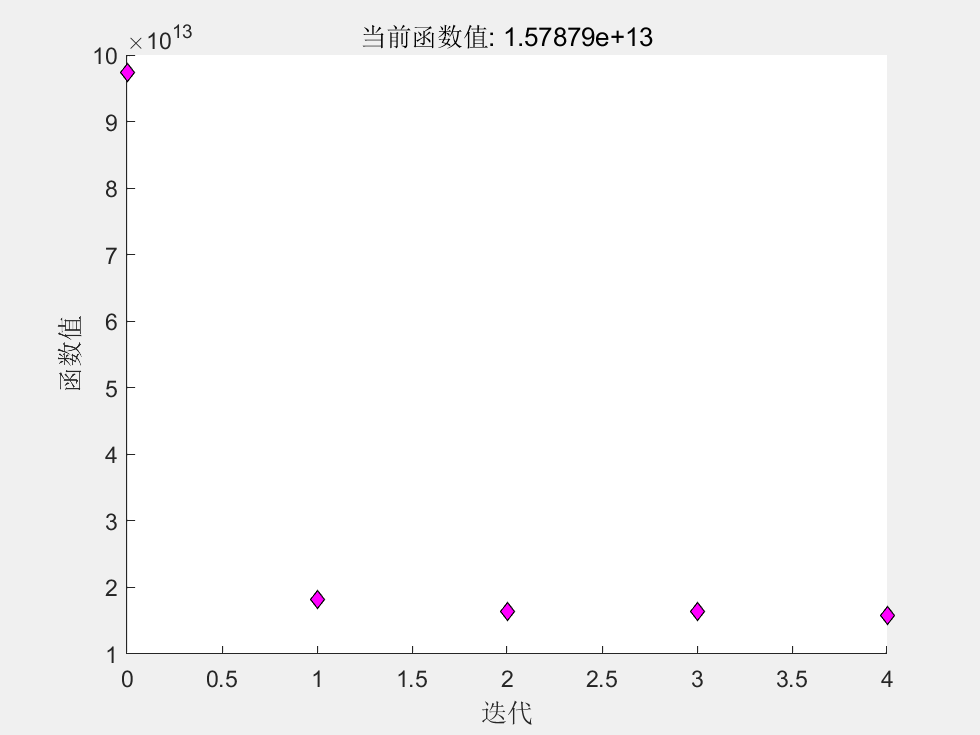


求解器过早停止。

fmincon 已停止，因为它超过函数计算限制，
options.MaxFunctionEvaluations = 7.000000e+01。



%{
% 测试每次循环的用时
data_container.Data.Iter = 0;
data_container.Data.Time_waiting = [];
time_before = datetime('now');
for i=1:10
    fprintf('第%d次循环\n',i)
    Pz = Pz_final + 0.1*i*max(Pz_final)*rand(size(Pz_final));% 它在优化过程中变化
    f = ObjFunc(Pz,bridge_clone,data_container,bridge_clone.OutputMethod.WorkPath,W,Maps_Base,X_sorted_points);
end
time_after = datetime('now');
% 10次循环等待时间占59.75秒
Time_waiting_total = sum(data_container.Data.Time_waiting) 
% 总时长1分15秒，即75秒
Time_diff = time_after - time_before
% 经过实测，从离开/prep7到进入/post1之间，需要花费7-8秒，猜测是GUI耗费了时间，因此必须使用ANSYS Batch
%}

% 优化相关参数
lb = zeros(size(Pz_final));
ub = 5*max(abs(Pz_final)) + zeros(size(Pz_final));
MaxIter = 5;
func = @(Pz) ObjFunc(Pz,bridge_clone,data_container,workspace,W,Maps_Base,X_sorted_points);
options = optimoptions('fmincon',...
                       'PlotFcn', 'optimplotfval',...
                       'ObjectiveLimit',(0.001*min(abs(Pz_final)))^2 * length(Pz_final),...
                       'DiffMinChange',0.001*min(abs(Pz_final)),...
                       'MaxFunctionEvaluations',(length(Pz_final)+1)*MaxIter);
[x,fval,exitflag,output] = fmincon(func,Pz_final, [], [], [], [], lb, ub, [], options);



% 优化完成之后
% 通知ANSYS：已经优化完成，你也可以退出循环了
outputStatus(workspace,"MATLAB_Call_ANSYS_Analyze.txt",-1);
if exitflag > 0
    outputStatus(workspace,"MATLAB_Good_End",1);% 优化正常结束
else
    outputStatus(workspace,"MATLAB_Bad_End",-1);% 优化发生错误
end


function f = ObjFunc(Pz,obj,data_container,workspace,W,Maps_Base,X_elem)
    % 输入：
    %   - InitStrain: 设计变量，初应变值数组。包含：斜拉索、吊索（为了减少设计变量个数，取对称的一边）
    %   - TargetStrain: 通过最优设计竖向力计算得到的此时的TargetStrain，
    %                   为了减少目标函数的计算量，在外部计算TargetStrain
    %   - hanger: Hanger对象（取对称的一边）
    %   - index_hanger: hanger在InitStrain中的index
    %   - cable: Cable对象（取对称的一边）
    %   - num_real: ANSYS中的实常数的编号。包含：斜拉索、吊索、主缆（对称的两边）
    %   - Area: 缆索的面积，ANSYS中实常数第1个参数，顺序由num_real控制。包含：斜拉索、吊索、主缆（对称的两边）
    %   - workspace: ANSYS运行的文件夹目录

    % 计算吊索力和主缆内力
    Y_final = obj.solveCableShape(Pz,data_container.Data.Y_0);
    data_container.Data.Y_0 = Y_final;
    
    % 计算斜拉索索力
    X_Pz = obj.XCoordOfPz;
    for i=1:length(obj.ReplacedStayedCable)
        stayed_cable = obj.ReplacedStayedCable(i);
        Point_Bottom = stayed_cable.findGirderPoint();
        X_Bottom = [Point_Bottom.X];
        P_girder_z = zeros(1,length(X_Bottom));
        for j=1:length(X_Pz)
            index = abs(X_Pz(j)-X_Bottom) < 1e-5;
            P_girder_z(index) = Pz(j);
        end
        stayed_cable.getP(P_girder_z);
    end
    % 将BaseModel的Map复制一份
    obj.Params.Map_OutputedPoint = cloneMap(Maps_Base{1});
    obj.Params.Map_MatlabLine2AnsysLine = cloneMap(Maps_Base{2});
    obj.Params.Map_AnsysLine2MatlabLine = cloneMap(Maps_Base{3});
    obj.Params.Map_MatlabLine2AnsysElem = cloneMap(Maps_Base{4});
    obj.Params.Map_AnsysElem2MatlabLine = cloneMap(Maps_Base{5});
    % outputCableSystem()中改变obj.Params.Map而不是Map_BaseModel
    outputCableSystem(obj);
    
    % 通知ANSYS，让其开始分析
    outputStatus(workspace,"MATLAB_Call_ANSYS_Analyze.txt",1); % ANSYS会将通知文件阅后即焚

    % MATLAB挂起，直到收到ANSYS通知
    waitForStatus(workspace,"ANSYS_Call_MATLAB_ObjFunc.txt");

    % ANSYS收到消息
    % ANSYS导入实常数
    % ANSYS进行一次分析
    % ANSYS输出Result.txt
    % ANSYS通知MATLAB，让其计算目标函数
    % ANSYS挂起

    % MATLAB收到ANSYS通知，通知文件阅后即焚
    if exist(fullfile(workspace,'ANSYS_Call_MATLAB_ObjFunc.txt'), 'file')
        delete(fullfile(workspace,"ANSYS_Call_MATLAB_ObjFunc.txt"))
    else
        error('ANSYS在时间内没有回调')
    end
    
    % 读入Result.txt
    RawData = inputData(workspace,"Result.txt",length(X_elem));
    
    force = RawData(1,:);
    INodeX = RawData(2,:);
    INodeY = RawData(3,:);
    INodeZ = RawData(4,:);
    JNodeX = RawData(5,:);
    JNodeY = RawData(6,:);
    JNodeZ = RawData(7,:);

    L = sqrt((INodeX-JNodeX).^2 + (INodeY-JNodeY).^2 + (INodeZ-JNodeZ).^2);
    Pz_solved = zeros(size(Pz));
    for i=1:length(X_Pz)
        force_vertical = force.*abs(JNodeZ-INodeZ)./(L);
        index = abs(X_Pz(i)-X_elem)<=1e-3;
        Pz_solved = sum(force_vertical(index) - L(index).*W(index)/2);
    end

    % 计算优化目标：与优化目标之间的MSE
    f = sum((Pz-Pz_solved).^2);
end

function data = inputData(folderPath, fileName, count_row, everyPauseSeconds, maxPauseSeconds)
    arguments
        folderPath {mustBeText}
        fileName {mustBeText}
        count_row {mustBeInteger}
        everyPauseSeconds {mustBeNumeric} = 0.005
        maxPauseSeconds {mustBeNumeric} = 10
    end
    % 数据文件路径
    dataFilePath = fullfile(folderPath, fileName);
    % lock文件路径
    splitted_filePath = strsplit(dataFilePath,'.');
    splitted_filePath(end) = {'.readlock'};
    readLockFilePath = strjoin(splitted_filePath,'');
    splitted_filePath(end) = {'.writelock'};
    writeLockFilePath = strjoin(splitted_filePath,'');
    % 1. 等待数据文件生成
    tic;
    while (~exist(dataFilePath, 'file')) || (exist(readLockFilePath,'file')) || (exist(writeLockFilePath,'file')) % 如果不存在、正在写出、正在写入文件，就等待
        pause(everyPauseSeconds);
        waitedSeconds = toc;
        if waitedSeconds > maxPauseSeconds
            disp(strcat('等待',dataFilePath,'时间超过', num2str(maxPauseSeconds), '秒'));
            break;
        end
    end
    % 2. 增加lock文件
    fileID = fopen(readLockFilePath, 'w');
    fclose(fileID);
    % 3. 读入数据文件
    fileID = fopen(dataFilePath, 'r');
    data = fscanf(fileID,'%e %e %e %e %e %e %e\n',[7,count_row]);
    fclose(fileID);
    % 4. 删除lock文件
    delete(readLockFilePath);
end

function outputStatus(folderPath, fileName, status)
    arguments
        folderPath {mustBeText}
        fileName {mustBeText}
        status = []
    end
    statusFilePath = fullfile(folderPath, fileName);
    % lock文件路径
    splitted_filePath = strsplit(statusFilePath,'.');
    splitted_filePath(end) = {'.readlock'};
    readLockFilePath = strjoin(splitted_filePath,'');
    splitted_filePath(end) = {'.writelock'};
    writeLockFilePath = strjoin(splitted_filePath,'');
    % 1. Lock文件删除
    tic;
    while (exist(readLockFilePath,'file')) || (exist(writeLockFilePath,'file'))
        pause(everyPauseSeconds);
        waitedSeconds = toc;
        if waitedSeconds > maxPauseSeconds
            disp(strcat('等待',dataFilePath,'时间超过', num2str(maxPauseSeconds), '秒'));
            break;
        end
    end
    % 2. 增加lock文件
    fileID = fopen(writeLockFilePath, 'w');
    fclose(fileID);
    if isempty(status)
        fileID = fopen(statusFilePath, 'w');
        fclose(fileID);
    elseif length(status)==1
        fileID = fopen(statusFilePath, 'w');
        fprintf(fileID, '%20.8E', status);
        fclose(fileID);
    end
    % 4. 删除lock文件
    delete(writeLockFilePath);
end

function waitForStatus(folderPath, fileName, everyPauseSeconds, maxPauseSeconds)
    arguments
        folderPath {mustBeText}
        fileName {mustBeText}
        everyPauseSeconds {mustBeNumeric} = 0.005
        maxPauseSeconds {mustBeNumeric} = 10
    end
    % 状态文件路径
    statusFilePath = fullfile(folderPath, fileName);
    % lock文件路径
    splitted_filePath = strsplit(statusFilePath,'.');
    splitted_filePath(end) = {'.readlock'};
    readLockFilePath = strjoin(splitted_filePath,'');
    splitted_filePath(end) = {'.writelock'};
    writeLockFilePath = strjoin(splitted_filePath,'');
    % 等待状态文件生成
    flag = true;
    tic;
    while (~exist(statusFilePath, 'file')) || (exist(readLockFilePath,'file')) || (exist(writeLockFilePath,'file'))
        pause(everyPauseSeconds);
        waitedSeconds = toc;
        if waitedSeconds > maxPauseSeconds
            fprintf('等待%s的时间超过%f秒，退出等待。\n',fileName,maxPauseSeconds);
            flag = false;
            break;
        end
    end
end

function outputBaseModel(obj)
    OutputMethod = obj.OutputMethod;
    OutputMethod.JobName = 'BaseModel';

    obj.OutputMethod.OutputObj = obj.OriginalBridge;
    OutputMethod.outputElementType();
    OutputMethod.outputMaterial();
    OutputMethod.outputSection();

    obj.OutputMethod.OutputObj = obj;
    OutputMethod.outputReal();
    OutputMethod.outputKeyPoint();
    OutputMethod.outputLine();
    OutputMethod.outputLineAttribution();
    OutputMethod.outputLineMesh();
    OutputMethod.outputConstraint();
    OutputMethod.outputCoupling();

    OutputMethod.outputMain('main_Base.mac','flag_Load',false,'flag_Solve',false);
end

function resumeCableSystem(obj)
    % 隐藏梁塔及其荷载和约束
    func = @(structure) [structure]; % function_handle，通过cellfun将cell转换为对象数组
    [girder_list,index_girder] = obj.findStructureByClass('Girder');
    obj.ReplacedGirder = cellfun(func,girder_list);
    [tower_list,index_tower] = obj.findStructureByClass('Tower');
    obj.ReplacedTower = cellfun(func,tower_list);
    [rigid_list,index_rigid] = obj.findStructureByClass('RigidBeam');
    obj.ReplacedRigidBeam = cellfun(func,rigid_list);

    replaced_structure_index = index_girder | index_tower | index_rigid;
    obj.MaterialList(replaced_structure_index) = [];
    obj.SectionList(replaced_structure_index) = [];
    obj.ElementTypeList(replaced_structure_index) = [];
    obj.ElementDivisionList(replaced_structure_index) = [];
    obj.StructureList(replaced_structure_index) = [];
    
    
    % 恢复
    for i=1:length(obj.ReplacedStayedCable)
        member = obj.ReplacedStayedCable(i);
        obj.updateList('Structure',member,'Section',member.Section.unique, ...
                       'Material',member.Material,'ElementType',member.ElementType,'ElementDivision',member.ElementDivisionNum)
    end
    for i=1:length(obj.ReplacedCable)
        member = obj.ReplacedCable(i);
        obj.updateList('Structure',member,'Section',member.Section.unique, ...
                       'Material',member.Material,'ElementType',member.ElementType,'ElementDivision',member.ElementDivisionNum)
    end
    for i=1:length(obj.ReplacedHanger)
        member = obj.ReplacedHanger(i);
        obj.updateList('Structure',member,'Section',member.Section.unique, ...
                       'Material',member.Material,'ElementType',member.ElementType,'ElementDivision',member.ElementDivisionNum)
    end

    % 恢复
    couplings = obj.DeletedCoupling;
    constraints = obj.DeletedConstraint;

    cell2array = @(c) [c];
    obj.DeletedCoupling = cellfun(cell2array,obj.CouplingList);
    obj.DeletedConstraint = cellfun(cell2array,obj.ConstraintList);

    array2cell = @(c) {c};
    obj.CouplingList = arrayfun(array2cell,couplings);
    obj.ConstraintList = arrayfun(array2cell,constraints);

end

function outputCableSystem(obj,Map_OutputedPoint,Map_MatlabLine2AnsysLine,Map_AnsysLine2MatlabLine,Map_MatlabLine2AnsysElem,Map_AnsysElem2MatlabLine)
    arguments
        obj
        Map_OutputedPoint = obj.Params.Map_OutputedPoint;
        Map_MatlabLine2AnsysLine = obj.Params.Map_MatlabLine2AnsysLine;
        Map_AnsysLine2MatlabLine = obj.Params.Map_AnsysLine2MatlabLine;
        Map_MatlabLine2AnsysElem = obj.Params.Map_MatlabLine2AnsysElem;
        Map_AnsysElem2MatlabLine = obj.Params.Map_AnsysElem2MatlabLine;
    end
    OutputMethod = obj.OutputMethod;
    OutputMethod.JobName = 'CableSystem';

    num_start_line = max(cell2mat(keys(Map_AnsysLine2MatlabLine)))+1;
    num_start_elem = max(cell2mat(keys(Map_AnsysElem2MatlabLine)))+1;

    OutputMethod.outputReal('defReal_CableSystem.mac');
    OutputMethod.outputKeyPoint('defKeyPoint_CableSystem.mac',Map_OutputedPoint);
    OutputMethod.outputLine('defLine_CableSystem.mac',num_start_line,Map_MatlabLine2AnsysLine,Map_AnsysLine2MatlabLine);
    OutputMethod.outputLineAttribution('defLineAttribution_CableSystem.mac');
    OutputMethod.outputLineMesh('defLineMesh_CableSystem.mac',num_start_elem,Map_MatlabLine2AnsysElem,Map_AnsysElem2MatlabLine);
    OutputMethod.outputConstraint('defConstraint_CableSystem.mac');
    OutputMethod.outputCoupling('defCoupling_CableSystem.mac');
    output_str = ['/prep7',newline,...
                  'resume,BaseModel,db',newline,...
                  '/input,defReal_CableSystem,mac,,,0',newline,...
                  '/input,defKeyPoint_CableSystem,mac,,,0',newline,...
                  '/input,defLine_CableSystem,mac,,,0',newline,...
                  '/input,defLineAttribution_CableSystem,mac,,,0',newline,...
                  '/input,defLineMesh_CableSystem,mac,,0',newline,...
                  '/input,defConstraint_CableSystem,mac,,,0',newline,...
                  '/input,defCoupling_CableSystem,mac,,,0'];
    obj.OutputMethod.outputAPDL(output_str,'main_CableSystem.mac','w');
end

function Map_clone = cloneMap(Map)
    keyset = keys(Map);
    valueset = values(Map);
    Map_clone = containers.Map(keyset,valueset);
end